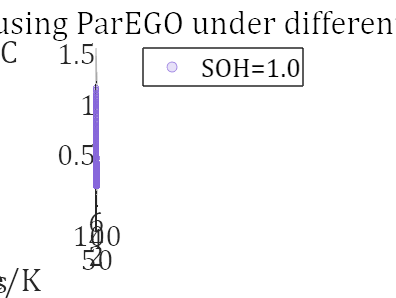

% 跑不同SOH实验时，需要对TrOpt、DISK、DGEA函数进行修改

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SOH = 100 %%%%%%%%%%%%%%%%%
% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_100_1.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);

最终指标为, 充电时间: 3859 分钟, 温升: 2.62 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 2976 分钟, 温升: 4.27 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 4256 分钟, 温升: 2.06 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3289 分钟, 温升: 3.46 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3557 分钟, 温升: 3.31 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3952 分钟, 温升: 3.15 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3922 分钟, 温升: 2.47 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3059 分钟, 温升: 3.98 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3449 分钟, 温升: 3.27 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3814 分钟, 温升: 2.87 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3449 分钟, 温升: 3.04 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3873 分钟, 温升: 3.69 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3586 分钟, 温升: 2.82 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3252 分钟, 温升: 3.09 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 4042 分钟, 温升: 2.31 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3672 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3082 分钟, 温升: 4.34 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2563 分钟, 温升: 4.73 度, 消耗寿命: 0.68 %...
最终指标为, 充电时间: 3802 分钟, 温升: 3.05 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3951 分钟, 温升: 2.38 度, 消耗寿命: 0.48 %...


ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_100for70_200_1','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);

最终指标为, 充电时间: 3859 分钟, 温升: 2.62 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 2976 分钟, 温升: 4.27 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 4256 分钟, 温升: 2.06 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3289 分钟, 温升: 3.46 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3557 分钟, 温升: 3.31 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3952 分钟, 温升: 3.15 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3922 分钟, 温升: 2.47 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3059 分钟, 温升: 3.98 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3449 分钟, 温升: 3.27 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3814 分钟, 温升: 2.87 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3449 分钟, 温升: 3.04 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3873 分钟, 温升: 3.69 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3586 分钟, 温升: 2.82 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3252 分钟, 温升: 3.09 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 4042 分钟, 温升: 2.31 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3672 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3082 分钟, 温升: 4.34 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2563 分钟, 温升: 4.73 度, 消耗寿命: 0.68 %...
最终指标为, 充电时间: 3802 分钟, 温升: 3.05 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3951 分钟, 温升: 2.38 度, 消耗寿命: 0.48 %...


最终指标为, 充电时间: 3859 分钟, 温升: 2.62 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 2976 分钟, 温升: 4.27 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 4256 分钟, 温升: 2.06 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3289 分钟, 温升: 3.46 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3557 分钟, 温升: 3.31 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3952 分钟, 温升: 3.15 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3922 分钟, 温升: 2.47 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3059 分钟, 温升: 3.98 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3449 分钟, 温升: 3.27 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3814 分钟, 温升: 2.87 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3449 分钟, 温升: 3.04 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3873 分钟, 温升: 3.69 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3586 分钟, 温升: 2.82 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3252 分钟, 温升: 3.09 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 4042 分钟, 温升: 2.31 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3672 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3082 分钟, 温升: 4.34 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2563 分钟, 温升: 4.73 度, 消耗寿命: 0.68 %...
最终指标为, 充电时间: 3802 分钟, 温升: 3.05 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3951 分钟, 温升: 2.38 度, 消耗寿命: 0.48 %...


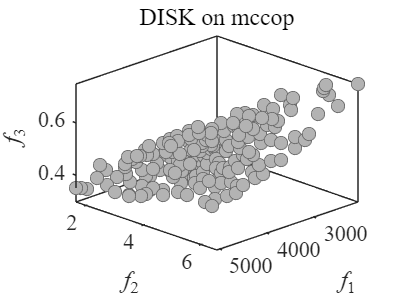

EEI_DATA = DB_EEI;
save('result/EEI_DATA_100for70_200_1','EEI_DATA');
% 方法三
platemo(1,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 4204 分钟, 温升: 2.41 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3461 分钟, 温升: 2.83 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3819 分钟, 温升: 3.14 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3238 分钟, 温升: 3.27 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3131 分钟, 温升: 3.15 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 2777 分钟, 温升: 4.64 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3621 分钟, 温升: 2.74 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3602 分钟, 温升: 3.95 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 2904 分钟, 温升: 3.47 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3814 分钟, 温升: 3.21 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3069 分钟, 温升: 4.15 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3927 分钟, 温升: 3.00 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 4010 分钟, 温升: 2.70 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3920 分钟, 温升: 2.35 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3152 分钟, 温升: 3.15 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3354 分钟, 温升: 2.99 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3338 分钟, 温升: 3.22 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 2429 分钟, 温升: 5.10 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3835 分钟, 温升: 2.93 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3176 分钟, 温升: 3.29 度, 消耗寿命: 0.49 %...


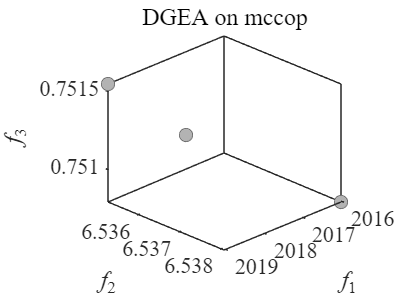

% 方法四
platemo(1,init_pop,'algorithm',@DGEA,'problem',@mccop);

% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_100_2.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);

最终指标为, 充电时间: 3479 分钟, 温升: 3.51 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3153 分钟, 温升: 3.98 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3400 分钟, 温升: 2.75 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 2711 分钟, 温升: 4.13 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3495 分钟, 温升: 4.16 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3797 分钟, 温升: 2.97 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3222 分钟, 温升: 4.17 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 2547 分钟, 温升: 4.95 度, 消耗寿命: 0.64 %...
最终指标为, 充电时间: 3654 分钟, 温升: 2.46 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3391 分钟, 温升: 2.96 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2468 分钟, 温升: 5.40 度, 消耗寿命: 0.70 %...
最终指标为, 充电时间: 3967 分钟, 温升: 2.67 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2519 分钟, 温升: 5.01 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 2910 分钟, 温升: 4.02 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3811 分钟, 温升: 2.93 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3500 分钟, 温升: 2.74 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3898 分钟, 温升: 3.38 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3419 分钟, 温升: 3.20 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 2480 分钟, 温升: 4.91 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 2801 分钟, 温升: 4.81 度, 消耗寿命: 0.63 %...


ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_100for70_200_2','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);

最终指标为, 充电时间: 3479 分钟, 温升: 3.51 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3153 分钟, 温升: 3.98 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3400 分钟, 温升: 2.75 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 2711 分钟, 温升: 4.13 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3495 分钟, 温升: 4.16 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3797 分钟, 温升: 2.97 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3222 分钟, 温升: 4.17 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 2547 分钟, 温升: 4.95 度, 消耗寿命: 0.64 %...
最终指标为, 充电时间: 3654 分钟, 温升: 2.46 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3391 分钟, 温升: 2.96 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2468 分钟, 温升: 5.40 度, 消耗寿命: 0.70 %...
最终指标为, 充电时间: 3967 分钟, 温升: 2.67 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2519 分钟, 温升: 5.01 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 2910 分钟, 温升: 4.02 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3811 分钟, 温升: 2.93 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3500 分钟, 温升: 2.74 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3898 分钟, 温升: 3.38 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3419 分钟, 温升: 3.20 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 2480 分钟, 温升: 4.91 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 2801 分钟, 温升: 4.81 度, 消耗寿命: 0.63 %...


最终指标为, 充电时间: 3479 分钟, 温升: 3.51 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3153 分钟, 温升: 3.98 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3400 分钟, 温升: 2.75 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 2711 分钟, 温升: 4.13 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3495 分钟, 温升: 4.16 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3797 分钟, 温升: 2.97 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3222 分钟, 温升: 4.17 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 2547 分钟, 温升: 4.95 度, 消耗寿命: 0.64 %...
最终指标为, 充电时间: 3654 分钟, 温升: 2.46 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3391 分钟, 温升: 2.96 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2468 分钟, 温升: 5.40 度, 消耗寿命: 0.70 %...
最终指标为, 充电时间: 3967 分钟, 温升: 2.67 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2519 分钟, 温升: 5.01 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 2910 分钟, 温升: 4.02 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3811 分钟, 温升: 2.93 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3500 分钟, 温升: 2.74 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3898 分钟, 温升: 3.38 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3419 分钟, 温升: 3.20 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 2480 分钟, 温升: 4.91 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 2801 分钟, 温升: 4.81 度, 消耗寿命: 0.63 %...


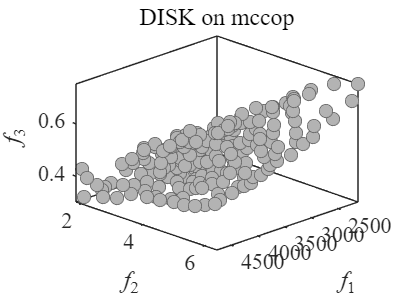

EEI_DATA = DB_EEI;
save('result/EEI_DATA_100for70_200_2','EEI_DATA');
% 方法三
platemo(2,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 3025 分钟, 温升: 4.19 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 2865 分钟, 温升: 4.58 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 4098 分钟, 温升: 2.04 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3366 分钟, 温升: 2.96 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 4342 分钟, 温升: 2.21 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3991 分钟, 温升: 3.44 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3258 分钟, 温升: 4.48 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 2670 分钟, 温升: 4.48 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 3045 分钟, 温升: 4.58 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 3085 分钟, 温升: 3.62 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 4666 分钟, 温升: 1.74 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3095 分钟, 温升: 3.99 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3545 分钟, 温升: 3.03 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 2673 分钟, 温升: 4.43 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 4164 分钟, 温升: 2.52 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 4339 分钟, 温升: 2.25 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3124 分钟, 温升: 3.10 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3279 分钟, 温升: 3.98 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3623 分钟, 温升: 2.62 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3375 分钟, 温升: 2.86 度, 消耗寿命: 0.46 %...


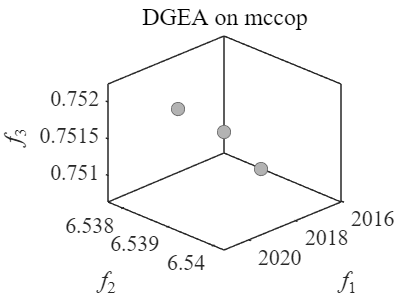

% 方法四
platemo(2,init_pop,'algorithm',@DGEA,'problem',@mccop);

% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_100_3.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);

最终指标为, 充电时间: 2930 分钟, 温升: 3.71 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 4186 分钟, 温升: 2.09 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 4114 分钟, 温升: 2.05 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3982 分钟, 温升: 3.65 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3152 分钟, 温升: 3.35 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3419 分钟, 温升: 4.28 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3532 分钟, 温升: 2.88 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 4128 分钟, 温升: 2.95 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 2844 分钟, 温升: 4.69 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 2787 分钟, 温升: 4.70 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3691 分钟, 温升: 2.61 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3797 分钟, 温升: 2.38 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3273 分钟, 温升: 3.00 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3405 分钟, 温升: 3.98 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3326 分钟, 温升: 3.21 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3113 分钟, 温升: 4.20 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3626 分钟, 温升: 3.77 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3272 分钟, 温升: 3.42 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3669 分钟, 温升: 3.70 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3975 分钟, 温升: 2.33 度, 消耗寿命: 0.40 %...


ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_100for70_200_3','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);

最终指标为, 充电时间: 2930 分钟, 温升: 3.71 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 4186 分钟, 温升: 2.09 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 4114 分钟, 温升: 2.05 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3982 分钟, 温升: 3.65 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3152 分钟, 温升: 3.35 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3419 分钟, 温升: 4.28 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3532 分钟, 温升: 2.88 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 4128 分钟, 温升: 2.95 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 2844 分钟, 温升: 4.69 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 2787 分钟, 温升: 4.70 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3691 分钟, 温升: 2.61 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3797 分钟, 温升: 2.38 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3273 分钟, 温升: 3.00 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3405 分钟, 温升: 3.98 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3326 分钟, 温升: 3.21 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3113 分钟, 温升: 4.20 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3626 分钟, 温升: 3.77 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3272 分钟, 温升: 3.42 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3669 分钟, 温升: 3.70 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3975 分钟, 温升: 2.33 度, 消耗寿命: 0.40 %...


最终指标为, 充电时间: 2930 分钟, 温升: 3.71 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 4186 分钟, 温升: 2.09 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 4114 分钟, 温升: 2.05 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3982 分钟, 温升: 3.65 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3152 分钟, 温升: 3.35 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3419 分钟, 温升: 4.28 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3532 分钟, 温升: 2.88 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 4128 分钟, 温升: 2.95 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 2844 分钟, 温升: 4.69 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 2787 分钟, 温升: 4.70 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3691 分钟, 温升: 2.61 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3797 分钟, 温升: 2.38 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3273 分钟, 温升: 3.00 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3405 分钟, 温升: 3.98 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3326 分钟, 温升: 3.21 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3113 分钟, 温升: 4.20 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3626 分钟, 温升: 3.77 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3272 分钟, 温升: 3.42 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3669 分钟, 温升: 3.70 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3975 分钟, 温升: 2.33 度, 消耗寿命: 0.40 %...


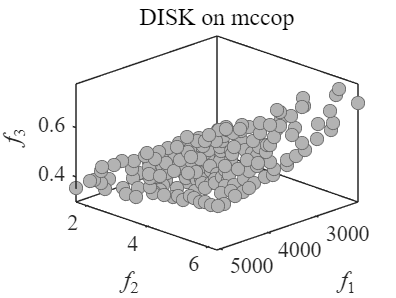

EEI_DATA = DB_EEI;
save('result/EEI_DATA_100for70_200_3','EEI_DATA');
% 方法三
platemo(3,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 2841 分钟, 温升: 3.93 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3494 分钟, 温升: 2.70 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3237 分钟, 温升: 4.08 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3228 分钟, 温升: 2.94 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3851 分钟, 温升: 3.38 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 4232 分钟, 温升: 2.38 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3379 分钟, 温升: 3.15 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3011 分钟, 温升: 4.15 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3269 分钟, 温升: 3.03 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3617 分钟, 温升: 3.00 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3094 分钟, 温升: 4.20 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3316 分钟, 温升: 2.80 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3267 分钟, 温升: 2.89 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 4300 分钟, 温升: 2.37 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 2821 分钟, 温升: 4.34 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3681 分钟, 温升: 3.23 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3601 分钟, 温升: 2.63 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2685 分钟, 温升: 4.34 度, 消耗寿命: 0.64 %...
最终指标为, 充电时间: 3546 分钟, 温升: 3.98 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3397 分钟, 温升: 4.17 度, 消耗寿命: 0.59 %...


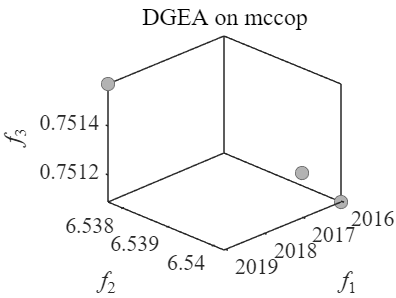

% 方法四
platemo(3,init_pop,'algorithm',@DGEA,'problem',@mccop);

% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_100_4.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);

最终指标为, 充电时间: 3474 分钟, 温升: 2.68 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3439 分钟, 温升: 3.28 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3054 分钟, 温升: 3.65 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3302 分钟, 温升: 3.85 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3442 分钟, 温升: 3.77 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 4040 分钟, 温升: 2.47 度, 消耗寿命: 0.37 %...
最终指标为, 充电时间: 4033 分钟, 温升: 2.97 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3909 分钟, 温升: 2.25 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3181 分钟, 温升: 3.10 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3183 分钟, 温升: 4.00 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3414 分钟, 温升: 3.79 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3017 分钟, 温升: 5.04 度, 消耗寿命: 0.66 %...
最终指标为, 充电时间: 3604 分钟, 温升: 4.15 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3202 分钟, 温升: 3.00 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3678 分钟, 温升: 3.05 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3158 分钟, 温升: 4.15 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 2861 分钟, 温升: 3.90 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3943 分钟, 温升: 2.32 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3663 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3758 分钟, 温升: 2.57 度, 消耗寿命: 0.43 %...


ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_100for70_200_4','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);

最终指标为, 充电时间: 3474 分钟, 温升: 2.68 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3439 分钟, 温升: 3.28 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3054 分钟, 温升: 3.65 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3302 分钟, 温升: 3.85 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3442 分钟, 温升: 3.77 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 4040 分钟, 温升: 2.47 度, 消耗寿命: 0.37 %...
最终指标为, 充电时间: 4033 分钟, 温升: 2.97 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3909 分钟, 温升: 2.25 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3181 分钟, 温升: 3.10 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3183 分钟, 温升: 4.00 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3414 分钟, 温升: 3.79 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3017 分钟, 温升: 5.04 度, 消耗寿命: 0.66 %...
最终指标为, 充电时间: 3604 分钟, 温升: 4.15 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3202 分钟, 温升: 3.00 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3678 分钟, 温升: 3.05 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3158 分钟, 温升: 4.15 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 2861 分钟, 温升: 3.90 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3943 分钟, 温升: 2.32 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3663 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3758 分钟, 温升: 2.57 度, 消耗寿命: 0.43 %...


最终指标为, 充电时间: 3474 分钟, 温升: 2.68 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3439 分钟, 温升: 3.28 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3054 分钟, 温升: 3.65 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3302 分钟, 温升: 3.85 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3442 分钟, 温升: 3.77 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 4040 分钟, 温升: 2.47 度, 消耗寿命: 0.37 %...
最终指标为, 充电时间: 4033 分钟, 温升: 2.97 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3909 分钟, 温升: 2.25 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3181 分钟, 温升: 3.10 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3183 分钟, 温升: 4.00 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3414 分钟, 温升: 3.79 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3017 分钟, 温升: 5.04 度, 消耗寿命: 0.66 %...
最终指标为, 充电时间: 3604 分钟, 温升: 4.15 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3202 分钟, 温升: 3.00 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3678 分钟, 温升: 3.05 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3158 分钟, 温升: 4.15 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 2861 分钟, 温升: 3.90 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3943 分钟, 温升: 2.32 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3663 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3758 分钟, 温升: 2.57 度, 消耗寿命: 0.43 %...


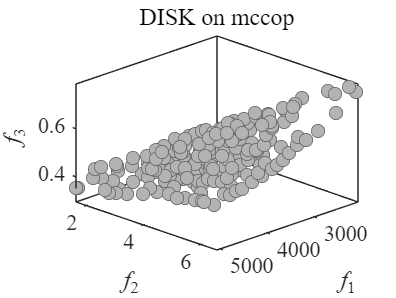

EEI_DATA = DB_EEI;
save('result/EEI_DATA_100for70_200_4','EEI_DATA');
% 方法三
platemo(4,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 3517 分钟, 温升: 3.45 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 2792 分钟, 温升: 4.54 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 3389 分钟, 温升: 4.17 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3689 分钟, 温升: 4.01 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2959 分钟, 温升: 4.47 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3468 分钟, 温升: 3.63 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3509 分钟, 温升: 3.67 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2618 分钟, 温升: 4.74 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3959 分钟, 温升: 2.65 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3251 分钟, 温升: 3.38 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3624 分钟, 温升: 2.67 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2746 分钟, 温升: 4.41 度, 消耗寿命: 0.63 %...
最终指标为, 充电时间: 4284 分钟, 温升: 2.34 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3924 分钟, 温升: 2.67 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3260 分钟, 温升: 2.98 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3443 分钟, 温升: 4.13 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3684 分钟, 温升: 2.91 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 4643 分钟, 温升: 1.73 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3127 分钟, 温升: 3.67 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2953 分钟, 温升: 4.01 度, 消耗寿命: 0.53 %...


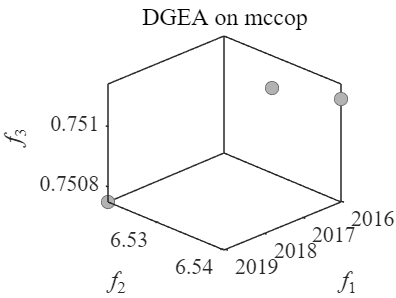

% 方法四
platemo(4,init_pop,'algorithm',@DGEA,'problem',@mccop);

% 2025/07/05
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_100_5.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);

最终指标为, 充电时间: 3266 分钟, 温升: 2.94 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3377 分钟, 温升: 4.20 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 4024 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2661 分钟, 温升: 5.05 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 4307 分钟, 温升: 2.48 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3432 分钟, 温升: 2.82 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3089 分钟, 温升: 3.84 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 4019 分钟, 温升: 2.46 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3335 分钟, 温升: 3.08 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3182 分钟, 温升: 4.51 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2654 分钟, 温升: 4.34 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3523 分钟, 温升: 3.34 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3024 分钟, 温升: 3.46 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3043 分钟, 温升: 3.85 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3398 分钟, 温升: 2.80 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3166 分钟, 温升: 4.21 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 2962 分钟, 温升: 3.79 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2904 分钟, 温升: 3.54 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3162 分钟, 温升: 3.07 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 4103 分钟, 温升: 2.81 度, 消耗寿命: 0.37 %...


ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_100for70_200_5','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);

最终指标为, 充电时间: 3266 分钟, 温升: 2.94 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3377 分钟, 温升: 4.20 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 4024 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2661 分钟, 温升: 5.05 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 4307 分钟, 温升: 2.48 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3432 分钟, 温升: 2.82 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3089 分钟, 温升: 3.84 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 4019 分钟, 温升: 2.46 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3335 分钟, 温升: 3.08 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3182 分钟, 温升: 4.51 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2654 分钟, 温升: 4.34 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3523 分钟, 温升: 3.34 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3024 分钟, 温升: 3.46 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3043 分钟, 温升: 3.85 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3398 分钟, 温升: 2.80 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3166 分钟, 温升: 4.21 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 2962 分钟, 温升: 3.79 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2904 分钟, 温升: 3.54 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3162 分钟, 温升: 3.07 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 4103 分钟, 温升: 2.81 度, 消耗寿命: 0.37 %...


最终指标为, 充电时间: 3266 分钟, 温升: 2.94 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3377 分钟, 温升: 4.20 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 4024 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2661 分钟, 温升: 5.05 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 4307 分钟, 温升: 2.48 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3432 分钟, 温升: 2.82 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3089 分钟, 温升: 3.84 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 4019 分钟, 温升: 2.46 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3335 分钟, 温升: 3.08 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3182 分钟, 温升: 4.51 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2654 分钟, 温升: 4.34 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3523 分钟, 温升: 3.34 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3024 分钟, 温升: 3.46 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3043 分钟, 温升: 3.85 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3398 分钟, 温升: 2.80 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3166 分钟, 温升: 4.21 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 2962 分钟, 温升: 3.79 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2904 分钟, 温升: 3.54 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3162 分钟, 温升: 3.07 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 4103 分钟, 温升: 2.81 度, 消耗寿命: 0.37 %...


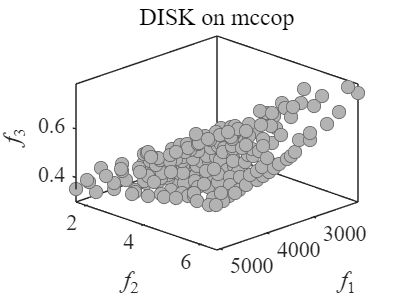

EEI_DATA = DB_EEI;
save('result/EEI_DATA_100for70_200_5','EEI_DATA');
% 方法三
platemo(5,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 3687 分钟, 温升: 3.31 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2977 分钟, 温升: 4.91 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 4581 分钟, 温升: 1.79 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 2854 分钟, 温升: 4.22 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3090 分钟, 温升: 3.41 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3928 分钟, 温升: 2.85 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 2544 分钟, 温升: 5.06 度, 消耗寿命: 0.64 %...
最终指标为, 充电时间: 3403 分钟, 温升: 3.01 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3213 分钟, 温升: 4.45 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3476 分钟, 温升: 2.88 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3074 分钟, 温升: 4.13 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3290 分钟, 温升: 3.88 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2997 分钟, 温升: 3.68 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3246 分钟, 温升: 3.04 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3311 分钟, 温升: 3.92 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3702 分钟, 温升: 2.36 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3738 分钟, 温升: 2.56 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3525 分钟, 温升: 3.49 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3537 分钟, 温升: 3.73 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 2404 分钟, 温升: 5.23 度, 消耗寿命: 0.63 %...


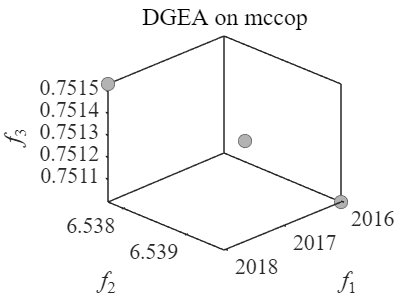

% 方法四
platemo(5,init_pop,'algorithm',@DGEA,'problem',@mccop);

最终指标为, 充电时间: 3859 分钟, 温升: 2.62 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 2976 分钟, 温升: 4.27 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 4256 分钟, 温升: 2.06 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3289 分钟, 温升: 3.46 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3557 分钟, 温升: 3.31 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3952 分钟, 温升: 3.15 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3922 分钟, 温升: 2.47 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3059 分钟, 温升: 3.98 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3449 分钟, 温升: 3.27 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3814 分钟, 温升: 2.87 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3449 分钟, 温升: 3.04 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3873 分钟, 温升: 3.69 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3586 分钟, 温升: 2.82 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3252 分钟, 温升: 3.09 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 4042 分钟, 温升: 2.31 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3672 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3082 分钟, 温升: 4.34 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2563 分钟, 温升: 4.73 度, 消耗寿命: 0.68 %...
最终指标为, 充电时间: 3802 分钟, 温升: 3.05 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3951 分钟, 温升: 2.38 度, 消耗寿命: 0.48 %...


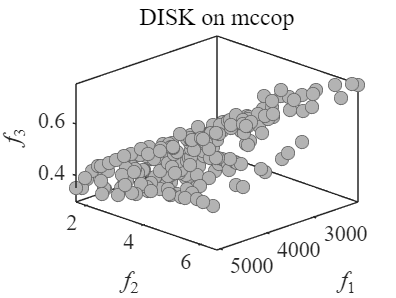

% 重跑实验
load("init_pop_100_1.mat");
platemo(1,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 3479 分钟, 温升: 3.51 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3153 分钟, 温升: 3.98 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3400 分钟, 温升: 2.75 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 2711 分钟, 温升: 4.13 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3495 分钟, 温升: 4.16 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3797 分钟, 温升: 2.97 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3222 分钟, 温升: 4.17 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 2547 分钟, 温升: 4.95 度, 消耗寿命: 0.64 %...
最终指标为, 充电时间: 3654 分钟, 温升: 2.46 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3391 分钟, 温升: 2.96 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2468 分钟, 温升: 5.40 度, 消耗寿命: 0.70 %...
最终指标为, 充电时间: 3967 分钟, 温升: 2.67 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2519 分钟, 温升: 5.01 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 2910 分钟, 温升: 4.02 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3811 分钟, 温升: 2.93 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3500 分钟, 温升: 2.74 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3898 分钟, 温升: 3.38 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3419 分钟, 温升: 3.20 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 2480 分钟, 温升: 4.91 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 2801 分钟, 温升: 4.81 度, 消耗寿命: 0.63 %...


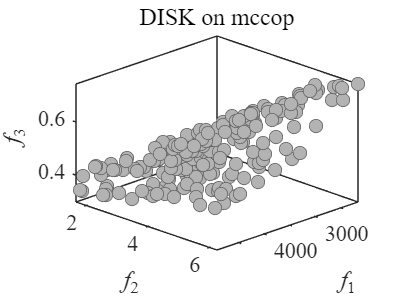


load("init_pop_100_2.mat");
platemo(2,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 2930 分钟, 温升: 3.71 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 4186 分钟, 温升: 2.09 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 4114 分钟, 温升: 2.05 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3982 分钟, 温升: 3.65 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3152 分钟, 温升: 3.35 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3419 分钟, 温升: 4.28 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3532 分钟, 温升: 2.88 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 4128 分钟, 温升: 2.95 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 2844 分钟, 温升: 4.69 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 2787 分钟, 温升: 4.70 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3691 分钟, 温升: 2.61 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3797 分钟, 温升: 2.38 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3273 分钟, 温升: 3.00 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3405 分钟, 温升: 3.98 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3326 分钟, 温升: 3.21 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3113 分钟, 温升: 4.20 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3626 分钟, 温升: 3.77 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3272 分钟, 温升: 3.42 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3669 分钟, 温升: 3.70 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3975 分钟, 温升: 2.33 度, 消耗寿命: 0.40 %...


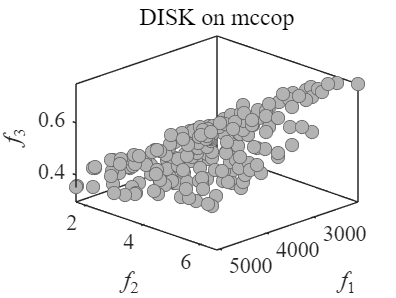


load("init_pop_100_3.mat");
platemo(3,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 3474 分钟, 温升: 2.68 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3439 分钟, 温升: 3.28 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3054 分钟, 温升: 3.65 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3302 分钟, 温升: 3.85 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3442 分钟, 温升: 3.77 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 4040 分钟, 温升: 2.47 度, 消耗寿命: 0.37 %...
最终指标为, 充电时间: 4033 分钟, 温升: 2.97 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3909 分钟, 温升: 2.25 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3181 分钟, 温升: 3.10 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3183 分钟, 温升: 4.00 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3414 分钟, 温升: 3.79 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3017 分钟, 温升: 5.04 度, 消耗寿命: 0.66 %...
最终指标为, 充电时间: 3604 分钟, 温升: 4.15 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3202 分钟, 温升: 3.00 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3678 分钟, 温升: 3.05 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3158 分钟, 温升: 4.15 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 2861 分钟, 温升: 3.90 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3943 分钟, 温升: 2.32 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3663 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3758 分钟, 温升: 2.57 度, 消耗寿命: 0.43 %...


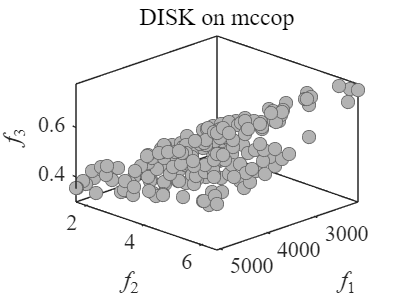


load("init_pop_100_4.mat");
platemo(4,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 3266 分钟, 温升: 2.94 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3377 分钟, 温升: 4.20 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 4024 分钟, 温升: 2.42 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2661 分钟, 温升: 5.05 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 4307 分钟, 温升: 2.48 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3432 分钟, 温升: 2.82 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3089 分钟, 温升: 3.84 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 4019 分钟, 温升: 2.46 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3335 分钟, 温升: 3.08 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3182 分钟, 温升: 4.51 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2654 分钟, 温升: 4.34 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3523 分钟, 温升: 3.34 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3024 分钟, 温升: 3.46 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3043 分钟, 温升: 3.85 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3398 分钟, 温升: 2.80 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3166 分钟, 温升: 4.21 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 2962 分钟, 温升: 3.79 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2904 分钟, 温升: 3.54 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3162 分钟, 温升: 3.07 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 4103 分钟, 温升: 2.81 度, 消耗寿命: 0.37 %...


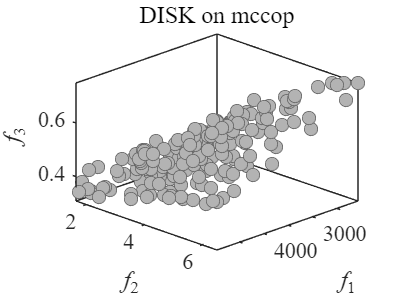


load("init_pop_100_5.mat");
platemo(5,init_pop,'algorithm',@DISK,'problem',@mccop);

最终指标为, 充电时间: 2660 分钟, 温升: 4.66 度, 消耗寿命: 0.63 %...
最终指标为, 充电时间: 3883 分钟, 温升: 2.35 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3306 分钟, 温升: 3.23 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3321 分钟, 温升: 3.71 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3246 分钟, 温升: 3.22 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3390 分钟, 温升: 2.81 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3556 分钟, 温升: 3.00 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3918 分钟, 温升: 2.71 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3773 分钟, 温升: 2.69 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3752 分钟, 温升: 3.03 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3114 分钟, 温升: 4.48 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 3055 分钟, 温升: 3.28 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3285 分钟, 温升: 3.81 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3284 分钟, 温升: 4.33 度, 消耗寿命: 0.63 %...
最终指标为, 充电时间: 3812 分钟, 温升: 2.39 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3430 分钟, 温升: 3.39 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3619 分钟, 温升: 2.99 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 2832 分钟, 温升: 5.54 度, 消耗寿命: 0.73 %...
最终指标为, 充电时间: 3802 分钟, 温升: 2.57 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3762 分钟, 温升: 2.71 度, 消耗寿命: 0.45 %...


最终指标为, 充电时间: 3982 分钟, 温升: 2.72 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3623 分钟, 温升: 2.51 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 11.00%), 44.28s passed...


最终指标为, 充电时间: 2864 分钟, 温升: 3.98 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3617 分钟, 温升: 2.75 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 12.00%), 47.73s passed...


最终指标为, 充电时间: 3204 分钟, 温升: 3.18 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3679 分钟, 温升: 2.55 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 13.00%), 51.16s passed...


最终指标为, 充电时间: 3319 分钟, 温升: 2.94 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3478 分钟, 温升: 3.01 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 14.00%), 54.58s passed...


最终指标为, 充电时间: 3211 分钟, 温升: 3.14 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 4038 分钟, 温升: 2.33 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 15.00%), 58.03s passed...


最终指标为, 充电时间: 3442 分钟, 温升: 2.95 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3194 分钟, 温升: 3.18 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 16.00%), 61.45s passed...


最终指标为, 充电时间: 2754 分钟, 温升: 4.27 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 3871 分钟, 温升: 2.81 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 17.00%), 64.87s passed...


最终指标为, 充电时间: 3871 分钟, 温升: 2.84 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3778 分钟, 温升: 2.78 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 18.00%), 68.35s passed...


最终指标为, 充电时间: 3369 分钟, 温升: 3.68 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3871 分钟, 温升: 2.84 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 19.00%), 71.80s passed...


最终指标为, 充电时间: 3893 分钟, 温升: 2.73 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3629 分钟, 温升: 3.02 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 20.00%), 75.35s passed...


最终指标为, 充电时间: 3202 分钟, 温升: 3.58 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3845 分钟, 温升: 2.36 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 21.00%), 78.78s passed...


最终指标为, 充电时间: 3168 分钟, 温升: 3.82 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3870 分钟, 温升: 2.35 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 22.00%), 82.25s passed...


最终指标为, 充电时间: 3725 分钟, 温升: 2.74 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3523 分钟, 温升: 2.75 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 23.00%), 85.77s passed...


最终指标为, 充电时间: 3878 分钟, 温升: 2.35 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3247 分钟, 温升: 3.50 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 24.00%), 89.24s passed...


最终指标为, 充电时间: 3343 分钟, 温升: 3.65 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 2623 分钟, 温升: 5.07 度, 消耗寿命: 0.66 %...


PIMD on 3-objective 5-variable mccop ( 25.00%), 92.60s passed...


最终指标为, 充电时间: 3097 分钟, 温升: 3.80 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 4256 分钟, 温升: 2.31 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 26.00%), 96.14s passed...


最终指标为, 充电时间: 3199 分钟, 温升: 3.33 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3036 分钟, 温升: 3.28 度, 消耗寿命: 0.54 %...


PIMD on 3-objective 5-variable mccop ( 27.00%), 99.56s passed...


最终指标为, 充电时间: 2520 分钟, 温升: 5.07 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 2544 分钟, 温升: 4.98 度, 消耗寿命: 0.64 %...


PIMD on 3-objective 5-variable mccop ( 28.00%), 102.88s passed...


最终指标为, 充电时间: 3979 分钟, 温升: 2.86 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3612 分钟, 温升: 3.09 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 29.00%), 106.44s passed...


最终指标为, 充电时间: 4014 分钟, 温升: 2.94 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3450 分钟, 温升: 3.41 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 30.00%), 109.91s passed...


最终指标为, 充电时间: 4249 分钟, 温升: 2.31 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3475 分钟, 温升: 3.87 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 31.00%), 113.53s passed...


最终指标为, 充电时间: 2625 分钟, 温升: 4.53 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 4336 分钟, 温升: 2.25 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 32.00%), 117.06s passed...


最终指标为, 充电时间: 4003 分钟, 温升: 2.81 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 3360 分钟, 温升: 3.05 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 33.00%), 120.52s passed...


最终指标为, 充电时间: 3792 分钟, 温升: 3.01 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3652 分钟, 温升: 3.95 度, 消耗寿命: 0.32 %...


PIMD on 3-objective 5-variable mccop ( 34.00%), 124.10s passed...


最终指标为, 充电时间: 2849 分钟, 温升: 3.59 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3278 分钟, 温升: 3.84 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 35.00%), 127.55s passed...


最终指标为, 充电时间: 3438 分钟, 温升: 3.04 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 4308 分钟, 温升: 2.30 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 36.00%), 131.37s passed...


最终指标为, 充电时间: 3145 分钟, 温升: 3.80 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2940 分钟, 温升: 3.44 度, 消耗寿命: 0.52 %...


PIMD on 3-objective 5-variable mccop ( 37.00%), 135.26s passed...


最终指标为, 充电时间: 3220 分钟, 温升: 3.13 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3466 分钟, 温升: 3.87 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 38.00%), 138.80s passed...


最终指标为, 充电时间: 3749 分钟, 温升: 2.88 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 4133 分钟, 温升: 2.62 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 39.00%), 142.34s passed...


最终指标为, 充电时间: 3869 分钟, 温升: 2.35 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3457 分钟, 温升: 2.79 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 40.00%), 145.88s passed...


最终指标为, 充电时间: 3408 分钟, 温升: 3.10 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 2469 分钟, 温升: 5.47 度, 消耗寿命: 0.68 %...


PIMD on 3-objective 5-variable mccop ( 41.00%), 149.34s passed...


最终指标为, 充电时间: 3533 分钟, 温升: 3.65 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2414 分钟, 温升: 5.31 度, 消耗寿命: 0.66 %...


PIMD on 3-objective 5-variable mccop ( 42.00%), 152.71s passed...


最终指标为, 充电时间: 2835 分钟, 温升: 4.50 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 2331 分钟, 温升: 5.40 度, 消耗寿命: 0.65 %...


PIMD on 3-objective 5-variable mccop ( 43.00%), 156.11s passed...


最终指标为, 充电时间: 2331 分钟, 温升: 5.39 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3381 分钟, 温升: 2.92 度, 消耗寿命: 0.49 %...
PIMD on 3-objective 5-variable mccop ( 44.00%), 159.49s passed...


最终指标为, 充电时间: 3603 分钟, 温升: 2.54 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 2944 分钟, 温升: 3.85 度, 消耗寿命: 0.51 %...
PIMD on 3-objective 5-variable mccop ( 45.00%), 163.26s passed...


最终指标为, 充电时间: 2470 分钟, 温升: 5.03 度, 消耗寿命: 0.64 %...
最终指标为, 充电时间: 3556 分钟, 温升: 3.99 度, 消耗寿命: 0.33 %...
PIMD on 3-objective 5-variable mccop ( 46.00%), 166.98s passed...


最终指标为, 充电时间: 3805 分钟, 温升: 2.57 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3261 分钟, 温升: 3.01 度, 消耗寿命: 0.48 %...
PIMD on 3-objective 5-variable mccop ( 47.00%), 170.57s passed...


最终指标为, 充电时间: 3506 分钟, 温升: 2.61 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2722 分钟, 温升: 4.18 度, 消耗寿命: 0.60 %...
PIMD on 3-objective 5-variable mccop ( 48.00%), 174.04s passed...


最终指标为, 充电时间: 3346 分钟, 温升: 3.19 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3653 分钟, 温升: 2.67 度, 消耗寿命: 0.48 %...
PIMD on 3-objective 5-variable mccop ( 49.00%), 177.75s passed...


最终指标为, 充电时间: 4306 分钟, 温升: 2.44 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3802 分钟, 温升: 2.57 度, 消耗寿命: 0.40 %...
PIMD on 3-objective 5-variable mccop ( 50.00%), 181.47s passed...


最终指标为, 充电时间: 2896 分钟, 温升: 4.20 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2915 分钟, 温升: 3.85 度, 消耗寿命: 0.50 %...
PIMD on 3-objective 5-variable mccop ( 51.00%), 185.22s passed...


最终指标为, 充电时间: 4091 分钟, 温升: 2.52 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 2531 分钟, 温升: 4.87 度, 消耗寿命: 0.64 %...
PIMD on 3-objective 5-variable mccop ( 52.00%), 189.18s passed...


最终指标为, 充电时间: 3898 分钟, 温升: 3.17 度, 消耗寿命: 0.32 %...
最终指标为, 充电时间: 4007 分钟, 温升: 2.99 度, 消耗寿命: 0.32 %...
PIMD on 3-objective 5-variable mccop ( 53.00%), 193.13s passed...


最终指标为, 充电时间: 2970 分钟, 温升: 3.34 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3614 分钟, 温升: 3.83 度, 消耗寿命: 0.33 %...
PIMD on 3-objective 5-variable mccop ( 54.00%), 196.87s passed...
最终指标为, 充电时间: 2784 分钟, 温升: 4.20 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3613 分钟, 温升: 3.79 度, 消耗寿命: 0.32 %...
PIMD on 3-objective 5-variable mccop ( 55.00%), 200.70s passed...


最终指标为, 充电时间: 2591 分钟, 温升: 4.80 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2849 分钟, 温升: 3.59 度, 消耗寿命: 0.57 %...
PIMD on 3-objective 5-variable mccop ( 56.00%), 204.94s passed...


最终指标为, 充电时间: 3024 分钟, 温升: 3.27 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3437 分钟, 温升: 2.68 度, 消耗寿命: 0.50 %...
PIMD on 3-objective 5-variable mccop ( 57.00%), 209.01s passed...


最终指标为, 充电时间: 2833 分钟, 温升: 4.50 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3720 分钟, 温升: 3.21 度, 消耗寿命: 0.34 %...
PIMD on 3-objective 5-variable mccop ( 58.00%), 213.09s passed...


最终指标为, 充电时间: 3293 分钟, 温升: 3.13 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3528 分钟, 温升: 3.00 度, 消耗寿命: 0.40 %...
PIMD on 3-objective 5-variable mccop ( 59.00%), 217.14s passed...


最终指标为, 充电时间: 3981 分钟, 温升: 2.79 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2984 分钟, 温升: 3.44 度, 消耗寿命: 0.52 %...
PIMD on 3-objective 5-variable mccop ( 60.00%), 220.83s passed...


最终指标为, 充电时间: 2331 分钟, 温升: 5.39 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 4295 分钟, 温升: 2.39 度, 消耗寿命: 0.34 %...
PIMD on 3-objective 5-variable mccop ( 61.00%), 224.61s passed...


最终指标为, 充电时间: 2963 分钟, 温升: 3.35 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3054 分钟, 温升: 3.29 度, 消耗寿命: 0.50 %...
PIMD on 3-objective 5-variable mccop ( 62.00%), 228.73s passed...


最终指标为, 充电时间: 3895 分钟, 温升: 2.73 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3141 分钟, 温升: 3.20 度, 消耗寿命: 0.48 %...
PIMD on 3-objective 5-variable mccop ( 63.00%), 232.48s passed...


最终指标为, 充电时间: 3868 分钟, 温升: 2.96 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2220 分钟, 温升: 5.76 度, 消耗寿命: 0.65 %...


PIMD on 3-objective 5-variable mccop ( 64.00%), 236.57s passed...


最终指标为, 充电时间: 2430 分钟, 温升: 5.25 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3880 分钟, 温升: 2.91 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 65.00%), 241.07s passed...


最终指标为, 充电时间: 2833 分钟, 温升: 4.50 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3965 分钟, 温升: 2.85 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 66.00%), 245.02s passed...


最终指标为, 充电时间: 3201 分钟, 温升: 3.14 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2550 分钟, 温升: 4.72 度, 消耗寿命: 0.64 %...


PIMD on 3-objective 5-variable mccop ( 67.00%), 248.66s passed...


最终指标为, 充电时间: 2969 分钟, 温升: 3.35 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2718 分钟, 温升: 4.30 度, 消耗寿命: 0.60 %...


PIMD on 3-objective 5-variable mccop ( 68.00%), 252.40s passed...


最终指标为, 充电时间: 3416 分钟, 温升: 4.10 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3429 分钟, 温升: 3.01 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 69.00%), 256.20s passed...


最终指标为, 充电时间: 3216 分钟, 温升: 3.37 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3883 分钟, 温升: 2.57 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 70.00%), 260.13s passed...


最终指标为, 充电时间: 3238 分钟, 温升: 3.33 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 2833 分钟, 温升: 4.51 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 71.00%), 263.75s passed...


最终指标为, 充电时间: 2902 分钟, 温升: 3.72 度, 消耗寿命: 0.54 %...


PIMD on 3-objective 5-variable mccop ( 71.50%), 265.91s passed...


最终指标为, 充电时间: 3661 分钟, 温升: 2.57 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 2824 分钟, 温升: 4.51 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 72.50%), 269.68s passed...


最终指标为, 充电时间: 3467 分钟, 温升: 2.87 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3776 分钟, 温升: 2.76 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 73.50%), 273.40s passed...


最终指标为, 充电时间: 4307 分钟, 温升: 2.44 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3483 分钟, 温升: 2.89 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 74.50%), 277.15s passed...


最终指标为, 充电时间: 2968 分钟, 温升: 3.35 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3489 分钟, 温升: 2.65 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 75.50%), 280.93s passed...


最终指标为, 充电时间: 2831 分钟, 温升: 4.50 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3936 分钟, 温升: 2.36 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 76.50%), 284.55s passed...


最终指标为, 充电时间: 2993 分钟, 温升: 4.21 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 2875 分钟, 温升: 4.30 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 77.50%), 288.24s passed...


最终指标为, 充电时间: 3521 分钟, 温升: 4.01 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3787 分钟, 温升: 2.93 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 78.50%), 291.99s passed...


最终指标为, 充电时间: 3518 分钟, 温升: 4.01 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3009 分钟, 温升: 3.29 度, 消耗寿命: 0.53 %...


PIMD on 3-objective 5-variable mccop ( 79.50%), 295.71s passed...


最终指标为, 充电时间: 4041 分钟, 温升: 2.33 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3355 分钟, 温升: 3.23 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 80.50%), 299.44s passed...


最终指标为, 充电时间: 2859 分钟, 温升: 3.60 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3828 分钟, 温升: 3.04 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 81.50%), 303.15s passed...


最终指标为, 充电时间: 2848 分钟, 温升: 4.45 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 2882 分钟, 温升: 4.51 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 82.50%), 306.79s passed...


最终指标为, 充电时间: 2789 分钟, 温升: 3.89 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 83.00%), 308.70s passed...


最终指标为, 充电时间: 3517 分钟, 温升: 2.64 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3413 分钟, 温升: 3.13 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 84.00%), 312.40s passed...


最终指标为, 充电时间: 3858 分钟, 温升: 2.40 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3032 分钟, 温升: 3.26 度, 消耗寿命: 0.53 %...


PIMD on 3-objective 5-variable mccop ( 85.00%), 316.17s passed...


最终指标为, 充电时间: 3407 分钟, 温升: 2.69 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3320 分钟, 温升: 2.91 度, 消耗寿命: 0.48 %...


PIMD on 3-objective 5-variable mccop ( 86.00%), 319.93s passed...


最终指标为, 充电时间: 3220 分钟, 温升: 3.66 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3393 分钟, 温升: 2.72 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 87.00%), 323.63s passed...


最终指标为, 充电时间: 3367 分钟, 温升: 3.26 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3500 分钟, 温升: 2.64 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 88.00%), 327.33s passed...


最终指标为, 充电时间: 3837 分钟, 温升: 2.92 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 3501 分钟, 温升: 3.18 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 89.00%), 331.13s passed...
最终指标为, 充电时间: 2227 分钟, 温升: 5.74 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3868 分钟, 温升: 2.38 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 90.00%), 334.81s passed...


最终指标为, 充电时间: 2359 分钟, 温升: 5.63 度, 消耗寿命: 0.68 %...
最终指标为, 充电时间: 3531 分钟, 温升: 3.93 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 91.00%), 338.50s passed...


最终指标为, 充电时间: 3935 分钟, 温升: 2.71 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 2709 分钟, 温升: 4.49 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 92.00%), 342.22s passed...


最终指标为, 充电时间: 3009 分钟, 温升: 3.35 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3288 分钟, 温升: 3.10 度, 消耗寿命: 0.53 %...


PIMD on 3-objective 5-variable mccop ( 93.00%), 345.96s passed...


最终指标为, 充电时间: 3913 分钟, 温升: 3.29 度, 消耗寿命: 0.31 %...
最终指标为, 充电时间: 3441 分钟, 温升: 3.12 度, 消耗寿命: 0.48 %...


PIMD on 3-objective 5-variable mccop ( 94.00%), 349.76s passed...


最终指标为, 充电时间: 3056 分钟, 温升: 3.28 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3292 分钟, 温升: 3.66 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 95.00%), 353.49s passed...


最终指标为, 充电时间: 3444 分钟, 温升: 2.69 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 4035 分钟, 温升: 2.44 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 96.00%), 357.49s passed...


最终指标为, 充电时间: 3987 分钟, 温升: 3.14 度, 消耗寿命: 0.31 %...
最终指标为, 充电时间: 2441 分钟, 温升: 5.19 度, 消耗寿命: 0.65 %...


PIMD on 3-objective 5-variable mccop ( 97.00%), 361.31s passed...


最终指标为, 充电时间: 3987 分钟, 温升: 3.14 度, 消耗寿命: 0.31 %...
最终指标为, 充电时间: 3692 分钟, 温升: 2.81 度, 消耗寿命: 0.40 %...


PIMD on 3-objective 5-variable mccop ( 98.00%), 365.23s passed...


最终指标为, 充电时间: 3553 分钟, 温升: 2.90 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3000 分钟, 温升: 3.38 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 99.00%), 368.94s passed...


最终指标为, 充电时间: 2801 分钟, 温升: 4.47 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2785 分钟, 温升: 3.96 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop (100.00%), 373.21s passed...


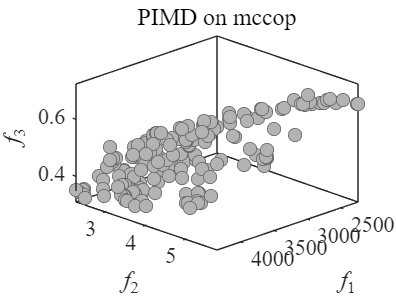

% 重跑实验
load("init_pop_100_1.mat");
platemo(1,init_pop,'algorithm',@PIMD,'problem',@mccop);

最终指标为, 充电时间: 3662 分钟, 温升: 2.57 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2903 分钟, 温升: 4.93 度, 消耗寿命: 0.64 %...
最终指标为, 充电时间: 2677 分钟, 温升: 4.37 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3557 分钟, 温升: 3.60 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3526 分钟, 温升: 3.35 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3013 分钟, 温升: 4.46 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3700 分钟, 温升: 2.83 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3430 分钟, 温升: 2.89 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 2634 分钟, 温升: 4.71 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3894 分钟, 温升: 3.00 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3800 分钟, 温升: 3.88 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3653 分钟, 温升: 2.56 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3459 分钟, 温升: 2.70 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3479 分钟, 温升: 4.33 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3519 分钟, 温升: 3.10 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 2702 分钟, 温升: 5.30 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 3477 分钟, 温升: 3.09 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3581 分钟, 温升: 2.93 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3754 分钟, 温升: 2.66 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3446 分钟, 温升: 2.99 度, 消耗寿命: 0.44 %...


最终指标为, 充电时间: 3468 分钟, 温升: 2.70 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3243 分钟, 温升: 3.61 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 11.00%), 39.01s passed...


最终指标为, 充电时间: 3188 分钟, 温升: 3.11 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3136 分钟, 温升: 3.14 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 12.00%), 42.62s passed...


最终指标为, 充电时间: 2909 分钟, 温升: 3.47 度, 消耗寿命: 0.56 %...


PIMD on 3-objective 5-variable mccop ( 12.50%), 44.37s passed...
最终指标为, 充电时间: 3350 分钟, 温升: 3.18 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3245 分钟, 温升: 3.32 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 13.50%), 47.86s passed...


最终指标为, 充电时间: 3776 分钟, 温升: 3.11 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 2676 分钟, 温升: 4.47 度, 消耗寿命: 0.62 %...


PIMD on 3-objective 5-variable mccop ( 14.50%), 51.33s passed...


最终指标为, 充电时间: 3207 分钟, 温升: 3.16 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3167 分钟, 温升: 3.20 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 15.50%), 54.88s passed...


最终指标为, 充电时间: 3192 分钟, 温升: 3.26 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3174 分钟, 温升: 3.95 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 16.50%), 58.26s passed...


最终指标为, 充电时间: 3735 分钟, 温升: 2.72 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 2909 分钟, 温升: 3.47 度, 消耗寿命: 0.56 %...


PIMD on 3-objective 5-variable mccop ( 17.50%), 61.78s passed...


最终指标为, 充电时间: 3375 分钟, 温升: 2.87 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3212 分钟, 温升: 3.11 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 18.50%), 65.38s passed...


最终指标为, 充电时间: 3054 分钟, 温升: 3.30 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3719 分钟, 温升: 2.78 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 19.50%), 68.84s passed...


最终指标为, 充电时间: 2897 分钟, 温升: 4.11 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3011 分钟, 温升: 3.37 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 20.50%), 72.36s passed...


最终指标为, 充电时间: 2533 分钟, 温升: 5.04 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3085 分钟, 温升: 3.21 度, 消耗寿命: 0.52 %...


PIMD on 3-objective 5-variable mccop ( 21.50%), 77.52s passed...


最终指标为, 充电时间: 2886 分钟, 温升: 4.20 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 2202 分钟, 温升: 5.99 度, 消耗寿命: 0.73 %...


PIMD on 3-objective 5-variable mccop ( 22.50%), 82.60s passed...


最终指标为, 充电时间: 3082 分钟, 温升: 3.21 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3102 分钟, 温升: 3.30 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 23.50%), 87.41s passed...


最终指标为, 充电时间: 2870 分钟, 温升: 4.30 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 2578 分钟, 温升: 4.97 度, 消耗寿命: 0.60 %...


PIMD on 3-objective 5-variable mccop ( 24.50%), 92.28s passed...


最终指标为, 充电时间: 2830 分钟, 温升: 4.67 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 25.00%), 94.59s passed...


最终指标为, 充电时间: 3185 分钟, 温升: 3.18 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3669 分钟, 温升: 3.92 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 26.00%), 99.16s passed...


最终指标为, 充电时间: 3447 分钟, 温升: 3.23 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 2669 分钟, 温升: 4.40 度, 消耗寿命: 0.59 %...


PIMD on 3-objective 5-variable mccop ( 27.00%), 103.70s passed...


最终指标为, 充电时间: 2493 分钟, 温升: 5.10 度, 消耗寿命: 0.68 %...
最终指标为, 充电时间: 2907 分钟, 温升: 3.57 度, 消耗寿命: 0.54 %...


PIMD on 3-objective 5-variable mccop ( 28.00%), 108.10s passed...


最终指标为, 充电时间: 2854 分钟, 温升: 4.29 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3080 分钟, 温升: 3.56 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 29.00%), 113.03s passed...
最终指标为, 充电时间: 3640 分钟, 温升: 3.89 度, 消耗寿命: 0.32 %...
最终指标为, 充电时间: 3178 分钟, 温升: 3.02 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 30.00%), 117.61s passed...


最终指标为, 充电时间: 2842 分钟, 温升: 3.76 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2527 分钟, 温升: 4.80 度, 消耗寿命: 0.66 %...


PIMD on 3-objective 5-variable mccop ( 31.00%), 122.11s passed...


最终指标为, 充电时间: 2804 分钟, 温升: 4.52 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2551 分钟, 温升: 4.98 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 32.00%), 126.50s passed...


最终指标为, 充电时间: 3772 分钟, 温升: 3.04 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 2817 分钟, 温升: 3.93 度, 消耗寿命: 0.58 %...


PIMD on 3-objective 5-variable mccop ( 33.00%), 131.07s passed...


最终指标为, 充电时间: 3439 分钟, 温升: 2.96 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3548 分钟, 温升: 2.95 度, 消耗寿命: 0.40 %...


PIMD on 3-objective 5-variable mccop ( 34.00%), 135.76s passed...


最终指标为, 充电时间: 2760 分钟, 温升: 4.06 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3408 分钟, 温升: 2.93 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 35.00%), 140.37s passed...


最终指标为, 充电时间: 3244 分钟, 温升: 3.53 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3633 分钟, 温升: 3.45 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 36.00%), 144.93s passed...


最终指标为, 充电时间: 2868 分钟, 温升: 3.97 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 2729 分钟, 温升: 4.42 度, 消耗寿命: 0.52 %...


PIMD on 3-objective 5-variable mccop ( 37.00%), 149.48s passed...


最终指标为, 充电时间: 3122 分钟, 温升: 3.12 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3051 分钟, 温升: 3.19 度, 消耗寿命: 0.53 %...


PIMD on 3-objective 5-variable mccop ( 38.00%), 153.99s passed...


最终指标为, 充电时间: 2726 分钟, 温升: 4.42 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3010 分钟, 温升: 3.89 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 39.00%), 158.47s passed...


最终指标为, 充电时间: 2747 分钟, 温升: 4.13 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 2978 分钟, 温升: 3.89 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 40.00%), 162.99s passed...


最终指标为, 充电时间: 3145 分钟, 温升: 3.12 度, 消耗寿命: 0.51 %...


PIMD on 3-objective 5-variable mccop ( 40.50%), 165.23s passed...


最终指标为, 充电时间: 3030 分钟, 温升: 3.26 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2433 分钟, 温升: 4.94 度, 消耗寿命: 0.64 %...


PIMD on 3-objective 5-variable mccop ( 41.50%), 169.63s passed...


最终指标为, 充电时间: 2968 分钟, 温升: 4.07 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3734 分钟, 温升: 3.19 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 42.50%), 174.21s passed...


最终指标为, 充电时间: 2139 分钟, 温升: 6.18 度, 消耗寿命: 0.74 %...
最终指标为, 充电时间: 3100 分钟, 温升: 3.16 度, 消耗寿命: 0.53 %...


PIMD on 3-objective 5-variable mccop ( 43.50%), 178.59s passed...


最终指标为, 充电时间: 2620 分钟, 温升: 4.44 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 3201 分钟, 温升: 4.20 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 44.50%), 183.30s passed...


最终指标为, 充电时间: 3560 分钟, 温升: 2.84 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 2607 分钟, 温升: 4.99 度, 消耗寿命: 0.52 %...


PIMD on 3-objective 5-variable mccop ( 45.50%), 187.84s passed...
最终指标为, 充电时间: 2827 分钟, 温升: 4.74 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3900 分钟, 温升: 2.72 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 46.50%), 192.44s passed...


最终指标为, 充电时间: 2574 分钟, 温升: 4.86 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 2995 分钟, 温升: 3.56 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 47.50%), 196.97s passed...


最终指标为, 充电时间: 3139 分钟, 温升: 4.40 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3884 分钟, 温升: 2.76 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 48.50%), 202.07s passed...


最终指标为, 充电时间: 3150 分钟, 温升: 3.68 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2815 分钟, 温升: 4.71 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 49.50%), 206.56s passed...


最终指标为, 充电时间: 4169 分钟, 温升: 2.42 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3193 分钟, 温升: 4.19 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 50.50%), 211.23s passed...
最终指标为, 充电时间: 4110 分钟, 温升: 2.40 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 2739 分钟, 温升: 4.12 度, 消耗寿命: 0.58 %...


PIMD on 3-objective 5-variable mccop ( 51.50%), 215.99s passed...


最终指标为, 充电时间: 2952 分钟, 温升: 3.37 度, 消耗寿命: 0.53 %...


PIMD on 3-objective 5-variable mccop ( 52.00%), 218.32s passed...


最终指标为, 充电时间: 3333 分钟, 温升: 4.16 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3196 分钟, 温升: 3.16 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 53.00%), 223.07s passed...


最终指标为, 充电时间: 2960 分钟, 温升: 3.99 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3730 分钟, 温升: 2.50 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 54.00%), 227.34s passed...


最终指标为, 充电时间: 4062 分钟, 温升: 2.44 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3146 分钟, 温升: 4.30 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 55.00%), 232.44s passed...


最终指标为, 充电时间: 3067 分钟, 温升: 3.20 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3685 分钟, 温升: 2.88 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 56.00%), 237.97s passed...


最终指标为, 充电时间: 3136 分钟, 温升: 3.09 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3126 分钟, 温升: 3.92 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 57.00%), 242.71s passed...


最终指标为, 充电时间: 3417 分钟, 温升: 3.81 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 2805 分钟, 温升: 4.67 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 58.00%), 247.91s passed...
最终指标为, 充电时间: 3771 分钟, 温升: 3.10 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 3925 分钟, 温升: 2.84 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 59.00%), 253.02s passed...


最终指标为, 充电时间: 3884 分钟, 温升: 2.76 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3629 分钟, 温升: 2.67 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 60.00%), 258.18s passed...


最终指标为, 充电时间: 2841 分钟, 温升: 3.76 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 2627 分钟, 温升: 4.41 度, 消耗寿命: 0.56 %...


PIMD on 3-objective 5-variable mccop ( 61.00%), 262.89s passed...


最终指标为, 充电时间: 2804 分钟, 温升: 4.69 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3729 分钟, 温升: 2.50 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 62.00%), 267.63s passed...


最终指标为, 充电时间: 3169 分钟, 温升: 3.02 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3317 分钟, 温升: 3.32 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 63.00%), 272.35s passed...


最终指标为, 充电时间: 3729 分钟, 温升: 2.51 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3155 分钟, 温升: 3.12 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 64.00%), 277.11s passed...


最终指标为, 充电时间: 3204 分钟, 温升: 3.48 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2986 分钟, 温升: 3.66 度, 消耗寿命: 0.54 %...


PIMD on 3-objective 5-variable mccop ( 65.00%), 281.86s passed...


最终指标为, 充电时间: 2879 分钟, 温升: 3.68 度, 消耗寿命: 0.56 %...


PIMD on 3-objective 5-variable mccop ( 65.50%), 284.53s passed...


最终指标为, 充电时间: 3062 分钟, 温升: 3.21 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2206 分钟, 温升: 5.86 度, 消耗寿命: 0.67 %...


PIMD on 3-objective 5-variable mccop ( 66.50%), 289.12s passed...


最终指标为, 充电时间: 3870 分钟, 温升: 2.73 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3339 分钟, 温升: 3.98 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 67.50%), 293.84s passed...


最终指标为, 充电时间: 2844 分钟, 温升: 3.76 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3032 分钟, 温升: 3.80 度, 消耗寿命: 0.51 %...


PIMD on 3-objective 5-variable mccop ( 68.50%), 298.49s passed...


最终指标为, 充电时间: 2661 分钟, 温升: 4.37 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 2924 分钟, 温升: 3.61 度, 消耗寿命: 0.56 %...


PIMD on 3-objective 5-variable mccop ( 69.50%), 303.23s passed...


最终指标为, 充电时间: 2994 分钟, 温升: 3.32 度, 消耗寿命: 0.52 %...


PIMD on 3-objective 5-variable mccop ( 70.00%), 305.61s passed...


最终指标为, 充电时间: 2529 分钟, 温升: 4.82 度, 消耗寿命: 0.63 %...
最终指标为, 充电时间: 3796 分钟, 温升: 2.54 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 71.00%), 310.28s passed...


最终指标为, 充电时间: 4185 分钟, 温升: 2.42 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3756 分钟, 温升: 3.16 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 72.00%), 315.12s passed...


最终指标为, 充电时间: 3713 分钟, 温升: 3.21 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2672 分钟, 温升: 4.39 度, 消耗寿命: 0.56 %...


PIMD on 3-objective 5-variable mccop ( 73.00%), 319.99s passed...


最终指标为, 充电时间: 2112 分钟, 温升: 6.29 度, 消耗寿命: 0.74 %...
最终指标为, 充电时间: 3434 分钟, 温升: 3.01 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 74.00%), 324.68s passed...


最终指标为, 充电时间: 2811 分钟, 温升: 4.65 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 2716 分钟, 温升: 5.28 度, 消耗寿命: 0.69 %...


PIMD on 3-objective 5-variable mccop ( 75.00%), 329.34s passed...


最终指标为, 充电时间: 3259 分钟, 温升: 3.27 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3434 分钟, 温升: 3.03 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 76.00%), 334.16s passed...


最终指标为, 充电时间: 4173 分钟, 温升: 2.44 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3206 分钟, 温升: 3.90 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 77.00%), 339.01s passed...


最终指标为, 充电时间: 3142 分钟, 温升: 3.69 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2836 分钟, 温升: 3.74 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 78.00%), 343.70s passed...


最终指标为, 充电时间: 3116 分钟, 温升: 3.13 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 2571 分钟, 温升: 4.68 度, 消耗寿命: 0.62 %...


PIMD on 3-objective 5-variable mccop ( 79.00%), 348.38s passed...


最终指标为, 充电时间: 3733 分钟, 温升: 2.50 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3532 分钟, 温升: 3.62 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 80.00%), 353.25s passed...


最终指标为, 充电时间: 3352 分钟, 温升: 3.53 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3874 分钟, 温升: 2.73 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 81.00%), 358.05s passed...


最终指标为, 充电时间: 3086 分钟, 温升: 3.15 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3484 分钟, 温升: 3.08 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 82.00%), 362.84s passed...


最终指标为, 充电时间: 3655 分钟, 温升: 2.61 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2605 分钟, 温升: 5.21 度, 消耗寿命: 0.68 %...


PIMD on 3-objective 5-variable mccop ( 83.00%), 367.50s passed...


最终指标为, 充电时间: 2806 分钟, 温升: 3.87 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3101 分钟, 温升: 3.22 度, 消耗寿命: 0.52 %...


PIMD on 3-objective 5-variable mccop ( 84.00%), 372.17s passed...


最终指标为, 充电时间: 3047 分钟, 温升: 3.26 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3014 分钟, 温升: 3.65 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 85.00%), 376.96s passed...


最终指标为, 充电时间: 3590 分钟, 温升: 3.38 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 2882 分钟, 温升: 3.53 度, 消耗寿命: 0.56 %...


PIMD on 3-objective 5-variable mccop ( 86.00%), 382.21s passed...


最终指标为, 充电时间: 2819 分钟, 温升: 4.04 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 2098 分钟, 温升: 6.24 度, 消耗寿命: 0.74 %...


PIMD on 3-objective 5-variable mccop ( 87.00%), 387.38s passed...


最终指标为, 充电时间: 4156 分钟, 温升: 2.71 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 2778 分钟, 温升: 4.76 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 88.00%), 392.25s passed...


最终指标为, 充电时间: 2567 分钟, 温升: 5.00 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3772 分钟, 温升: 2.70 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 89.00%), 397.03s passed...


最终指标为, 充电时间: 3633 分钟, 温升: 3.45 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 3835 分钟, 温升: 2.89 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 90.00%), 401.88s passed...


最终指标为, 充电时间: 3729 分钟, 温升: 2.50 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3336 分钟, 温升: 3.84 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 91.00%), 406.73s passed...


最终指标为, 充电时间: 2778 分钟, 温升: 4.04 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3676 分钟, 温升: 3.50 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 92.00%), 411.49s passed...
最终指标为, 充电时间: 3777 分钟, 温升: 2.91 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 2978 分钟, 温升: 3.78 度, 消耗寿命: 0.51 %...


PIMD on 3-objective 5-variable mccop ( 93.00%), 416.28s passed...


最终指标为, 充电时间: 3344 分钟, 温升: 3.31 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 2855 分钟, 温升: 3.63 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 94.00%), 421.13s passed...


最终指标为, 充电时间: 2828 分钟, 温升: 4.39 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 2764 分钟, 温升: 4.02 度, 消耗寿命: 0.59 %...


PIMD on 3-objective 5-variable mccop ( 95.00%), 425.84s passed...


最终指标为, 充电时间: 3192 分钟, 温升: 3.26 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3695 分钟, 温升: 2.55 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 96.00%), 430.73s passed...


最终指标为, 充电时间: 3099 分钟, 温升: 3.91 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 2877 分钟, 温升: 3.94 度, 消耗寿命: 0.53 %...


PIMD on 3-objective 5-variable mccop ( 97.00%), 435.55s passed...


最终指标为, 充电时间: 3493 分钟, 温升: 4.07 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3240 分钟, 温升: 3.29 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 98.00%), 440.32s passed...


最终指标为, 充电时间: 3492 分钟, 温升: 4.04 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3390 分钟, 温升: 3.11 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 99.00%), 445.08s passed...


最终指标为, 充电时间: 3205 分钟, 温升: 3.48 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2845 分钟, 温升: 4.26 度, 消耗寿命: 0.51 %...


PIMD on 3-objective 5-variable mccop (100.00%), 450.46s passed...


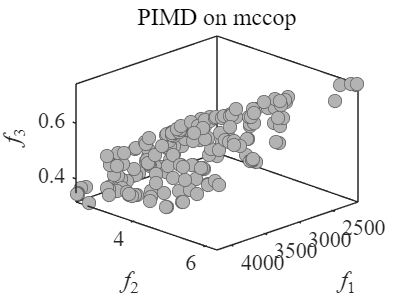


load("init_pop_100_2.mat");
platemo(2,init_pop,'algorithm',@PIMD,'problem',@mccop);

最终指标为, 充电时间: 3848 分钟, 温升: 3.79 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3189 分钟, 温升: 4.15 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 2745 分钟, 温升: 4.35 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3277 分钟, 温升: 2.96 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3091 分钟, 温升: 4.02 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3989 分钟, 温升: 2.40 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3600 分钟, 温升: 3.13 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 4300 分钟, 温升: 2.60 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3269 分钟, 温升: 3.90 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3116 分钟, 温升: 4.44 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3309 分钟, 温升: 3.48 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3963 分钟, 温升: 3.42 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2499 分钟, 温升: 5.56 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 2833 分钟, 温升: 4.03 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3326 分钟, 温升: 2.98 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3108 分钟, 温升: 3.45 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 3454 分钟, 温升: 2.94 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 4031 分钟, 温升: 2.55 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3335 分钟, 温升: 3.07 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3732 分钟, 温升: 2.38 度, 消耗寿命: 0.46 %...


最终指标为, 充电时间: 3018 分钟, 温升: 3.38 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 2842 分钟, 温升: 3.99 度, 消耗寿命: 0.59 %...


PIMD on 3-objective 5-variable mccop ( 11.00%), 49.91s passed...


最终指标为, 充电时间: 3564 分钟, 温升: 2.89 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3735 分钟, 温升: 2.86 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 12.00%), 54.62s passed...


最终指标为, 充电时间: 3791 分钟, 温升: 2.92 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3023 分钟, 温升: 3.80 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 13.00%), 59.17s passed...


最终指标为, 充电时间: 3115 分钟, 温升: 3.89 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3289 分钟, 温升: 3.16 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 14.00%), 63.63s passed...


最终指标为, 充电时间: 4143 分钟, 温升: 2.17 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3831 分钟, 温升: 2.53 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 15.00%), 68.35s passed...


最终指标为, 充电时间: 3111 分钟, 温升: 3.97 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3825 分钟, 温升: 2.30 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 16.00%), 72.89s passed...


最终指标为, 充电时间: 3422 分钟, 温升: 3.00 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 16.50%), 75.24s passed...


最终指标为, 充电时间: 3116 分钟, 温升: 3.56 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3632 分钟, 温升: 4.08 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 17.50%), 79.88s passed...


最终指标为, 充电时间: 3723 分钟, 温升: 2.77 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 2571 分钟, 温升: 4.88 度, 消耗寿命: 0.54 %...


PIMD on 3-objective 5-variable mccop ( 18.50%), 84.46s passed...


最终指标为, 充电时间: 2469 分钟, 温升: 5.60 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 2810 分钟, 温升: 4.26 度, 消耗寿命: 0.54 %...


PIMD on 3-objective 5-variable mccop ( 19.50%), 88.88s passed...


最终指标为, 充电时间: 2841 分钟, 温升: 4.04 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3496 分钟, 温升: 3.55 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 20.50%), 93.43s passed...


最终指标为, 充电时间: 3255 分钟, 温升: 3.54 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2289 分钟, 温升: 5.59 度, 消耗寿命: 0.62 %...


PIMD on 3-objective 5-variable mccop ( 21.50%), 97.96s passed...


最终指标为, 充电时间: 2771 分钟, 温升: 4.17 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3595 分钟, 温升: 2.84 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 22.50%), 102.50s passed...


最终指标为, 充电时间: 4123 分钟, 温升: 2.59 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3374 分钟, 温升: 3.06 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 23.50%), 107.16s passed...


最终指标为, 充电时间: 2328 分钟, 温升: 5.57 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 2500 分钟, 温升: 5.20 度, 消耗寿命: 0.62 %...


PIMD on 3-objective 5-variable mccop ( 24.50%), 111.49s passed...


最终指标为, 充电时间: 3310 分钟, 温升: 2.99 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2991 分钟, 温升: 4.46 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 25.50%), 115.94s passed...


最终指标为, 充电时间: 3317 分钟, 温升: 3.82 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3416 分钟, 温升: 2.76 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 26.50%), 120.26s passed...


最终指标为, 充电时间: 2378 分钟, 温升: 5.37 度, 消耗寿命: 0.63 %...
最终指标为, 充电时间: 2903 分钟, 温升: 3.50 度, 消耗寿命: 0.54 %...


PIMD on 3-objective 5-variable mccop ( 27.50%), 124.55s passed...


最终指标为, 充电时间: 3808 分钟, 温升: 2.89 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 4041 分钟, 温升: 2.61 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 28.50%), 128.65s passed...


最终指标为, 充电时间: 2497 分钟, 温升: 4.97 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3643 分钟, 温升: 3.25 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 29.50%), 133.08s passed...


最终指标为, 充电时间: 3655 分钟, 温升: 3.01 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3337 分钟, 温升: 3.10 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 30.50%), 138.01s passed...


最终指标为, 充电时间: 4118 分钟, 温升: 2.59 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3981 分钟, 温升: 2.55 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 31.50%), 143.05s passed...


最终指标为, 充电时间: 4338 分钟, 温升: 2.33 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 2307 分钟, 温升: 5.53 度, 消耗寿命: 0.60 %...


PIMD on 3-objective 5-variable mccop ( 32.50%), 147.61s passed...


最终指标为, 充电时间: 3901 分钟, 温升: 2.57 度, 消耗寿命: 0.37 %...
最终指标为, 充电时间: 3445 分钟, 温升: 3.07 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 33.50%), 152.13s passed...


最终指标为, 充电时间: 3609 分钟, 温升: 2.56 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3652 分钟, 温升: 3.01 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 34.50%), 157.19s passed...


最终指标为, 充电时间: 2991 分钟, 温升: 3.34 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 2946 分钟, 温升: 4.19 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 35.50%), 161.81s passed...


最终指标为, 充电时间: 2363 分钟, 温升: 5.18 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 3129 分钟, 温升: 3.55 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 36.50%), 166.39s passed...


最终指标为, 充电时间: 3523 分钟, 温升: 2.98 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3628 分钟, 温升: 2.55 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 37.50%), 171.49s passed...


最终指标为, 充电时间: 2897 分钟, 温升: 3.60 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3650 分钟, 温升: 2.96 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 38.50%), 176.35s passed...


最终指标为, 充电时间: 3080 分钟, 温升: 3.89 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3606 分钟, 温升: 3.12 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 39.50%), 181.08s passed...


最终指标为, 充电时间: 2826 分钟, 温升: 3.93 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 2737 分钟, 温升: 3.98 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 40.50%), 185.53s passed...


最终指标为, 充电时间: 2642 分钟, 温升: 4.64 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3759 分钟, 温升: 2.50 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 41.50%), 190.20s passed...


最终指标为, 充电时间: 3628 分钟, 温升: 2.53 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3584 分钟, 温升: 3.60 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 42.50%), 194.90s passed...


最终指标为, 充电时间: 3774 分钟, 温升: 2.96 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3429 分钟, 温升: 3.71 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 43.50%), 199.73s passed...


最终指标为, 充电时间: 3582 分钟, 温升: 3.57 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 3358 分钟, 温升: 3.24 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 44.50%), 204.43s passed...


最终指标为, 充电时间: 3377 分钟, 温升: 3.08 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 2942 分钟, 温升: 4.21 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 45.50%), 208.99s passed...


最终指标为, 充电时间: 3318 分钟, 温升: 3.82 度, 消耗寿命: 0.37 %...
最终指标为, 充电时间: 3927 分钟, 温升: 2.24 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 46.50%), 213.94s passed...


最终指标为, 充电时间: 4186 分钟, 温升: 2.39 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3806 分钟, 温升: 2.89 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 47.50%), 218.84s passed...


最终指标为, 充电时间: 3981 分钟, 温升: 2.55 度, 消耗寿命: 0.37 %...
最终指标为, 充电时间: 3402 分钟, 温升: 4.06 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 48.50%), 223.50s passed...


最终指标为, 充电时间: 3699 分钟, 温升: 2.62 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3114 分钟, 温升: 3.31 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 49.50%), 228.12s passed...


最终指标为, 充电时间: 3804 分钟, 温升: 2.89 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3393 分钟, 温升: 4.05 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 50.50%), 232.86s passed...


最终指标为, 充电时间: 3427 分钟, 温升: 3.09 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3799 分钟, 温升: 2.97 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 51.50%), 237.52s passed...


最终指标为, 充电时间: 4337 分钟, 温升: 2.38 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3764 分钟, 温升: 2.89 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 52.50%), 242.38s passed...


最终指标为, 充电时间: 4516 分钟, 温升: 2.10 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 4155 分钟, 温升: 2.19 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 53.50%), 247.29s passed...


最终指标为, 充电时间: 2941 分钟, 温升: 4.21 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 4587 分钟, 温升: 2.09 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 54.50%), 252.26s passed...


最终指标为, 充电时间: 3409 分钟, 温升: 3.06 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 4060 分钟, 温升: 2.91 度, 消耗寿命: 0.32 %...


PIMD on 3-objective 5-variable mccop ( 55.50%), 257.21s passed...


最终指标为, 充电时间: 4393 分钟, 温升: 2.44 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 2673 分钟, 温升: 4.16 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 56.50%), 261.96s passed...


最终指标为, 充电时间: 2802 分钟, 温升: 3.93 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 4641 分钟, 温升: 2.18 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 57.50%), 266.69s passed...


最终指标为, 充电时间: 2838 分钟, 温升: 4.53 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3158 分钟, 温升: 3.17 度, 消耗寿命: 0.48 %...


PIMD on 3-objective 5-variable mccop ( 58.50%), 271.38s passed...
最终指标为, 充电时间: 2984 分钟, 温升: 3.36 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 2645 分钟, 温升: 4.69 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 59.50%), 276.02s passed...


最终指标为, 充电时间: 2861 分钟, 温升: 4.07 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3220 分钟, 温升: 3.29 度, 消耗寿命: 0.51 %...


PIMD on 3-objective 5-variable mccop ( 60.50%), 280.70s passed...


最终指标为, 充电时间: 3990 分钟, 温升: 3.06 度, 消耗寿命: 0.32 %...
最终指标为, 充电时间: 4132 分钟, 温升: 2.37 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 61.50%), 285.54s passed...


最终指标为, 充电时间: 3261 分钟, 温升: 3.08 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3369 分钟, 温升: 3.81 度, 消耗寿命: 0.40 %...


PIMD on 3-objective 5-variable mccop ( 62.50%), 290.29s passed...


最终指标为, 充电时间: 3390 分钟, 温升: 4.05 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3278 分钟, 温升: 3.07 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 63.50%), 294.93s passed...


最终指标为, 充电时间: 3049 分钟, 温升: 4.10 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3315 分钟, 温升: 3.08 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 64.50%), 299.65s passed...


最终指标为, 充电时间: 3291 分钟, 温升: 3.20 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 4631 分钟, 温升: 2.24 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 65.50%), 304.77s passed...


最终指标为, 充电时间: 3162 分钟, 温升: 3.77 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 2288 分钟, 温升: 5.58 度, 消耗寿命: 0.62 %...


PIMD on 3-objective 5-variable mccop ( 66.50%), 309.54s passed...


最终指标为, 充电时间: 4335 分钟, 温升: 2.44 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 3511 分钟, 温升: 3.08 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 67.50%), 314.45s passed...


最终指标为, 充电时间: 2860 分钟, 温升: 3.76 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 4143 分钟, 温升: 2.17 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 68.50%), 319.18s passed...


最终指标为, 充电时间: 3758 分钟, 温升: 2.93 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3392 分钟, 温升: 3.85 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 69.50%), 324.01s passed...


最终指标为, 充电时间: 3459 分钟, 温升: 3.58 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 4410 分钟, 温升: 2.44 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 70.50%), 328.90s passed...


最终指标为, 充电时间: 3444 分钟, 温升: 3.55 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3681 分钟, 温升: 3.13 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 71.50%), 333.68s passed...


最终指标为, 充电时间: 3606 分钟, 温升: 2.68 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2821 分钟, 温升: 3.90 度, 消耗寿命: 0.53 %...


PIMD on 3-objective 5-variable mccop ( 72.50%), 338.43s passed...


最终指标为, 充电时间: 3308 分钟, 温升: 3.08 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3826 分钟, 温升: 3.64 度, 消耗寿命: 0.31 %...


PIMD on 3-objective 5-variable mccop ( 73.50%), 343.24s passed...


最终指标为, 充电时间: 3857 分钟, 温升: 2.83 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 2287 分钟, 温升: 5.59 度, 消耗寿命: 0.62 %...
PIMD on 3-objective 5-variable mccop ( 74.50%), 347.92s passed...


最终指标为, 充电时间: 2792 分钟, 温升: 3.91 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3737 分钟, 温升: 3.01 度, 消耗寿命: 0.35 %...
PIMD on 3-objective 5-variable mccop ( 75.50%), 352.70s passed...


最终指标为, 充电时间: 3532 分钟, 温升: 2.98 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3439 分钟, 温升: 3.26 度, 消耗寿命: 0.38 %...
PIMD on 3-objective 5-variable mccop ( 76.50%), 357.46s passed...


最终指标为, 充电时间: 3889 分钟, 温升: 3.07 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3345 分钟, 温升: 3.58 度, 消耗寿命: 0.40 %...
PIMD on 3-objective 5-variable mccop ( 77.50%), 362.37s passed...


最终指标为, 充电时间: 2586 分钟, 温升: 4.57 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3616 分钟, 温升: 2.57 度, 消耗寿命: 0.48 %...
PIMD on 3-objective 5-variable mccop ( 78.50%), 367.12s passed...


最终指标为, 充电时间: 2291 分钟, 温升: 5.55 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3409 分钟, 温升: 3.06 度, 消耗寿命: 0.42 %...
PIMD on 3-objective 5-variable mccop ( 79.50%), 371.88s passed...


最终指标为, 充电时间: 3310 分钟, 温升: 3.14 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3851 分钟, 温升: 2.99 度, 消耗寿命: 0.34 %...
PIMD on 3-objective 5-variable mccop ( 80.50%), 376.79s passed...


最终指标为, 充电时间: 3089 分钟, 温升: 3.34 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2708 分钟, 温升: 4.70 度, 消耗寿命: 0.49 %...
PIMD on 3-objective 5-variable mccop ( 81.50%), 381.45s passed...


最终指标为, 充电时间: 3054 分钟, 温升: 4.04 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 2281 分钟, 温升: 5.39 度, 消耗寿命: 0.65 %...


PIMD on 3-objective 5-variable mccop ( 82.50%), 386.09s passed...


最终指标为, 充电时间: 3956 分钟, 温升: 2.59 度, 消耗寿命: 0.37 %...
最终指标为, 充电时间: 3480 分钟, 温升: 2.71 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 83.50%), 391.08s passed...


最终指标为, 充电时间: 3347 分钟, 温升: 3.16 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 4230 分钟, 温升: 2.20 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 84.50%), 395.88s passed...


最终指标为, 充电时间: 3916 分钟, 温升: 2.44 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 85.00%), 398.50s passed...


最终指标为, 充电时间: 3578 分钟, 温升: 3.53 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3762 分钟, 温升: 2.52 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 86.00%), 403.34s passed...


最终指标为, 充电时间: 4562 分钟, 温升: 2.10 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2824 分钟, 温升: 4.28 度, 消耗寿命: 0.48 %...


PIMD on 3-objective 5-variable mccop ( 87.00%), 408.27s passed...


最终指标为, 充电时间: 3814 分钟, 温升: 2.29 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3829 分钟, 温升: 3.33 度, 消耗寿命: 0.32 %...


PIMD on 3-objective 5-variable mccop ( 88.00%), 413.22s passed...


最终指标为, 充电时间: 3290 分钟, 温升: 3.50 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2783 分钟, 温升: 4.17 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 89.00%), 418.02s passed...


最终指标为, 充电时间: 3690 分钟, 温升: 3.05 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 4631 分钟, 温升: 2.24 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 90.00%), 423.04s passed...


最终指标为, 充电时间: 3676 分钟, 温升: 3.06 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 4023 分钟, 温升: 2.84 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 91.00%), 427.99s passed...


最终指标为, 充电时间: 3722 分钟, 温升: 2.46 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 3431 分钟, 温升: 3.61 度, 消耗寿命: 0.49 %...


PIMD on 3-objective 5-variable mccop ( 92.00%), 432.88s passed...


最终指标为, 充电时间: 3460 分钟, 温升: 2.96 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3128 分钟, 温升: 3.21 度, 消耗寿命: 0.48 %...


PIMD on 3-objective 5-variable mccop ( 93.00%), 437.77s passed...


最终指标为, 充电时间: 3459 分钟, 温升: 2.98 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3768 分钟, 温升: 3.87 度, 消耗寿命: 0.31 %...


PIMD on 3-objective 5-variable mccop ( 94.00%), 442.49s passed...


最终指标为, 充电时间: 3007 分钟, 温升: 3.30 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3132 分钟, 温升: 3.12 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 95.00%), 447.35s passed...


最终指标为, 充电时间: 2969 分钟, 温升: 3.34 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 4005 分钟, 温升: 2.44 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 96.00%), 452.25s passed...


最终指标为, 充电时间: 4595 分钟, 温升: 2.33 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3057 分钟, 温升: 3.19 度, 消耗寿命: 0.52 %...


PIMD on 3-objective 5-variable mccop ( 97.00%), 457.13s passed...


最终指标为, 充电时间: 2303 分钟, 温升: 5.44 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 4508 分钟, 温升: 2.11 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 98.00%), 461.88s passed...


最终指标为, 充电时间: 3268 分钟, 温升: 3.66 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 4078 分钟, 温升: 2.58 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 99.00%), 466.89s passed...


最终指标为, 充电时间: 3497 分钟, 温升: 2.70 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3003 分钟, 温升: 4.49 度, 消耗寿命: 0.40 %...


PIMD on 3-objective 5-variable mccop (100.00%), 472.22s passed...


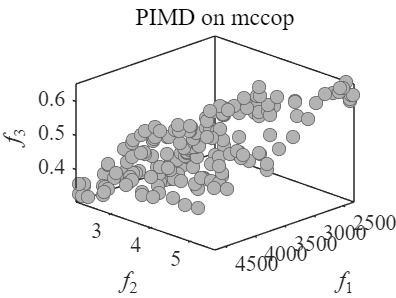


load("init_pop_100_3.mat");
platemo(3,init_pop,'algorithm',@PIMD,'problem',@mccop);

最终指标为, 充电时间: 3638 分钟, 温升: 3.14 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 4501 分钟, 温升: 2.13 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 2624 分钟, 温升: 5.11 度, 消耗寿命: 0.71 %...
最终指标为, 充电时间: 3155 分钟, 温升: 3.51 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3350 分钟, 温升: 3.14 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 2694 分钟, 温升: 4.93 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3260 分钟, 温升: 3.97 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3159 分钟, 温升: 4.20 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 4072 分钟, 温升: 2.10 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3022 分钟, 温升: 4.80 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3261 分钟, 温升: 3.54 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 2877 分钟, 温升: 3.87 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3371 分钟, 温升: 2.95 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 4015 分钟, 温升: 2.23 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3516 分钟, 温升: 2.83 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3942 分钟, 温升: 2.70 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3637 分钟, 温升: 3.07 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 4404 分钟, 温升: 1.80 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3284 分钟, 温升: 3.05 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 2971 分钟, 温升: 3.31 度, 消耗寿命: 0.54 %...


最终指标为, 充电时间: 2815 分钟, 温升: 4.90 度, 消耗寿命: 0.69 %...
最终指标为, 充电时间: 4486 分钟, 温升: 2.03 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 11.00%), 58.04s passed...


最终指标为, 充电时间: 4684 分钟, 温升: 1.99 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 3695 分钟, 温升: 2.79 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 12.00%), 63.28s passed...


最终指标为, 充电时间: 2431 分钟, 温升: 5.03 度, 消耗寿命: 0.69 %...
最终指标为, 充电时间: 2743 分钟, 温升: 3.97 度, 消耗寿命: 0.56 %...


PIMD on 3-objective 5-variable mccop ( 13.00%), 67.92s passed...


最终指标为, 充电时间: 3233 分钟, 温升: 4.18 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3405 分钟, 温升: 3.04 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 14.00%), 73.12s passed...


最终指标为, 充电时间: 3538 分钟, 温升: 2.78 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3979 分钟, 温升: 2.65 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 15.00%), 77.98s passed...


最终指标为, 充电时间: 3409 分钟, 温升: 2.95 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3639 分钟, 温升: 3.16 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 16.00%), 82.75s passed...


最终指标为, 充电时间: 3499 分钟, 温升: 3.17 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3192 分钟, 温升: 4.28 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 17.00%), 87.40s passed...


最终指标为, 充电时间: 2971 分钟, 温升: 3.31 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 4247 分钟, 温升: 2.29 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 18.00%), 92.05s passed...


最终指标为, 充电时间: 2872 分钟, 温升: 3.86 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 4400 分钟, 温升: 1.81 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 19.00%), 96.83s passed...


最终指标为, 充电时间: 3212 分钟, 温升: 4.18 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3248 分钟, 温升: 3.15 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 20.00%), 101.50s passed...


最终指标为, 充电时间: 3510 分钟, 温升: 2.77 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3497 分钟, 温升: 2.79 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 21.00%), 106.08s passed...


最终指标为, 充电时间: 2415 分钟, 温升: 5.03 度, 消耗寿命: 0.69 %...
最终指标为, 充电时间: 3191 分钟, 温升: 3.59 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 22.00%), 110.65s passed...


最终指标为, 充电时间: 2900 分钟, 温升: 3.56 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 4271 分钟, 温升: 2.60 度, 消耗寿命: 0.32 %...


PIMD on 3-objective 5-variable mccop ( 23.00%), 115.33s passed...


最终指标为, 充电时间: 3960 分钟, 温升: 3.06 度, 消耗寿命: 0.32 %...
最终指标为, 充电时间: 3626 分钟, 温升: 3.13 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 24.00%), 119.92s passed...


最终指标为, 充电时间: 4472 分钟, 温升: 2.25 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2524 分钟, 温升: 4.74 度, 消耗寿命: 0.66 %...


PIMD on 3-objective 5-variable mccop ( 25.00%), 124.58s passed...


最终指标为, 充电时间: 3651 分钟, 温升: 2.77 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3095 分钟, 温升: 3.22 度, 消耗寿命: 0.51 %...


PIMD on 3-objective 5-variable mccop ( 26.00%), 129.38s passed...


最终指标为, 充电时间: 2646 分钟, 温升: 5.03 度, 消耗寿命: 0.66 %...
最终指标为, 充电时间: 3306 分钟, 温升: 3.03 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 27.00%), 133.92s passed...


最终指标为, 充电时间: 3579 分钟, 温升: 2.95 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3896 分钟, 温升: 2.92 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 28.00%), 138.64s passed...


最终指标为, 充电时间: 3867 分钟, 温升: 2.91 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 4138 分钟, 温升: 2.60 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 29.00%), 143.56s passed...


最终指标为, 充电时间: 3192 分钟, 温升: 4.14 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3751 分钟, 温升: 2.48 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 30.00%), 148.20s passed...


最终指标为, 充电时间: 3703 分钟, 温升: 3.06 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 2701 分钟, 温升: 4.62 度, 消耗寿命: 0.63 %...


PIMD on 3-objective 5-variable mccop ( 31.00%), 152.87s passed...


最终指标为, 充电时间: 2399 分钟, 温升: 5.03 度, 消耗寿命: 0.69 %...
最终指标为, 充电时间: 2902 分钟, 温升: 3.79 度, 消耗寿命: 0.59 %...


PIMD on 3-objective 5-variable mccop ( 32.00%), 157.45s passed...


最终指标为, 充电时间: 4682 分钟, 温升: 2.01 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2480 分钟, 温升: 5.36 度, 消耗寿命: 0.68 %...


PIMD on 3-objective 5-variable mccop ( 33.00%), 162.19s passed...


最终指标为, 充电时间: 2415 分钟, 温升: 5.03 度, 消耗寿命: 0.69 %...
最终指标为, 充电时间: 4734 分钟, 温升: 1.76 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 34.00%), 166.99s passed...


最终指标为, 充电时间: 2515 分钟, 温升: 5.03 度, 消耗寿命: 0.68 %...
最终指标为, 充电时间: 2843 分钟, 温升: 4.51 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 35.00%), 171.54s passed...


最终指标为, 充电时间: 3790 分钟, 温升: 2.91 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 4145 分钟, 温升: 2.41 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 36.00%), 176.42s passed...


最终指标为, 充电时间: 3556 分钟, 温升: 3.53 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 2655 分钟, 温升: 4.19 度, 消耗寿命: 0.62 %...


PIMD on 3-objective 5-variable mccop ( 37.00%), 181.04s passed...


最终指标为, 充电时间: 2489 分钟, 温升: 5.19 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 2953 分钟, 温升: 3.41 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 38.00%), 185.62s passed...


最终指标为, 充电时间: 4033 分钟, 温升: 2.98 度, 消耗寿命: 0.32 %...
最终指标为, 充电时间: 3226 分钟, 温升: 3.11 度, 消耗寿命: 0.49 %...


PIMD on 3-objective 5-variable mccop ( 39.00%), 190.33s passed...


最终指标为, 充电时间: 3368 分钟, 温升: 2.93 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3167 分钟, 温升: 3.24 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 40.00%), 194.98s passed...


最终指标为, 充电时间: 3624 分钟, 温升: 2.67 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3199 分钟, 温升: 3.45 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 41.00%), 199.78s passed...


最终指标为, 充电时间: 2435 分钟, 温升: 5.33 度, 消耗寿命: 0.68 %...
最终指标为, 充电时间: 3845 分钟, 温升: 2.67 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 42.00%), 204.35s passed...


最终指标为, 充电时间: 2435 分钟, 温升: 5.33 度, 消耗寿命: 0.68 %...
最终指标为, 充电时间: 3897 分钟, 温升: 2.80 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 43.00%), 208.95s passed...


最终指标为, 充电时间: 2884 分钟, 温升: 3.64 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3920 分钟, 温升: 3.50 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 44.00%), 213.66s passed...


最终指标为, 充电时间: 3095 分钟, 温升: 3.22 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 4043 分钟, 温升: 2.74 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 45.00%), 218.40s passed...


最终指标为, 充电时间: 3842 分钟, 温升: 3.20 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3110 分钟, 温升: 4.01 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 46.00%), 223.18s passed...


最终指标为, 充电时间: 3463 分钟, 温升: 2.90 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 4331 分钟, 温升: 1.89 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 47.00%), 227.98s passed...


最终指标为, 充电时间: 3520 分钟, 温升: 3.05 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3087 分钟, 温升: 3.87 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 48.00%), 232.72s passed...


最终指标为, 充电时间: 3863 分钟, 温升: 2.89 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3737 分钟, 温升: 3.79 度, 消耗寿命: 0.31 %...


PIMD on 3-objective 5-variable mccop ( 49.00%), 237.57s passed...


最终指标为, 充电时间: 3086 分钟, 温升: 3.69 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 2900 分钟, 温升: 3.63 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 50.00%), 242.29s passed...


最终指标为, 充电时间: 3863 分钟, 温升: 2.89 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3537 分钟, 温升: 2.72 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 51.00%), 247.11s passed...


最终指标为, 充电时间: 4681 分钟, 温升: 2.00 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 4044 分钟, 温升: 2.58 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 52.00%), 252.11s passed...


最终指标为, 充电时间: 2897 分钟, 温升: 3.52 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 4071 分钟, 温升: 2.15 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 53.00%), 256.91s passed...


最终指标为, 充电时间: 2954 分钟, 温升: 3.33 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 4323 分钟, 温升: 1.96 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 54.00%), 261.66s passed...


最终指标为, 充电时间: 3268 分钟, 温升: 3.26 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 2952 分钟, 温升: 3.38 度, 消耗寿命: 0.54 %...


PIMD on 3-objective 5-variable mccop ( 55.00%), 266.44s passed...


最终指标为, 充电时间: 2134 分钟, 温升: 6.22 度, 消耗寿命: 0.73 %...
最终指标为, 充电时间: 3191 分钟, 温升: 3.59 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 56.00%), 271.12s passed...


最终指标为, 充电时间: 2501 分钟, 温升: 4.76 度, 消耗寿命: 0.66 %...
最终指标为, 充电时间: 4731 分钟, 温升: 1.75 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 57.00%), 275.93s passed...


最终指标为, 充电时间: 2366 分钟, 温升: 5.02 度, 消耗寿命: 0.67 %...
最终指标为, 充电时间: 3579 分钟, 温升: 2.84 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 58.00%), 280.68s passed...


最终指标为, 充电时间: 2971 分钟, 温升: 3.32 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 4069 分钟, 温升: 2.89 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 59.00%), 285.62s passed...


最终指标为, 充电时间: 2951 分钟, 温升: 3.35 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 2179 分钟, 温升: 5.94 度, 消耗寿命: 0.72 %...


PIMD on 3-objective 5-variable mccop ( 60.00%), 290.28s passed...


最终指标为, 充电时间: 2962 分钟, 温升: 3.33 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3443 分钟, 温升: 4.16 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 61.00%), 295.05s passed...


最终指标为, 充电时间: 3200 分钟, 温升: 3.13 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 4880 分钟, 温升: 1.74 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 62.00%), 300.01s passed...


最终指标为, 充电时间: 3551 分钟, 温升: 3.32 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 62.50%), 302.49s passed...


最终指标为, 充电时间: 3926 分钟, 温升: 2.57 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 2319 分钟, 温升: 5.68 度, 消耗寿命: 0.60 %...


PIMD on 3-objective 5-variable mccop ( 63.50%), 307.27s passed...


最终指标为, 充电时间: 4055 分钟, 温升: 2.89 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3663 分钟, 温升: 2.88 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 64.50%), 312.13s passed...


最终指标为, 充电时间: 4606 分钟, 温升: 1.77 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3473 分钟, 温升: 2.92 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 65.50%), 317.13s passed...


最终指标为, 充电时间: 2902 分钟, 温升: 3.88 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 4238 分钟, 温升: 1.93 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 66.50%), 322.08s passed...


最终指标为, 充电时间: 3168 分钟, 温升: 3.20 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 67.00%), 324.58s passed...


最终指标为, 充电时间: 2472 分钟, 温升: 4.72 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 4418 分钟, 温升: 1.98 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 68.00%), 329.67s passed...


最终指标为, 充电时间: 2882 分钟, 温升: 3.55 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3251 分钟, 温升: 3.62 度, 消耗寿命: 0.40 %...


PIMD on 3-objective 5-variable mccop ( 69.00%), 334.28s passed...


最终指标为, 充电时间: 3964 分钟, 温升: 2.69 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3762 分钟, 温升: 3.24 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 70.00%), 339.35s passed...


最终指标为, 充电时间: 2135 分钟, 温升: 6.20 度, 消耗寿命: 0.72 %...
最终指标为, 充电时间: 3991 分钟, 温升: 2.80 度, 消耗寿命: 0.34 %...
PIMD on 3-objective 5-variable mccop ( 71.00%), 344.10s passed...


最终指标为, 充电时间: 2641 分钟, 温升: 4.23 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 4431 分钟, 温升: 2.13 度, 消耗寿命: 0.35 %...
PIMD on 3-objective 5-variable mccop ( 72.00%), 348.97s passed...


最终指标为, 充电时间: 4135 分钟, 温升: 2.60 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3083 分钟, 温升: 3.53 度, 消耗寿命: 0.46 %...
PIMD on 3-objective 5-variable mccop ( 73.00%), 353.81s passed...


最终指标为, 充电时间: 3419 分钟, 温升: 2.89 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3027 分钟, 温升: 3.71 度, 消耗寿命: 0.45 %...
PIMD on 3-objective 5-variable mccop ( 74.00%), 358.57s passed...


最终指标为, 充电时间: 3162 分钟, 温升: 3.57 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 4176 分钟, 温升: 2.66 度, 消耗寿命: 0.33 %...
PIMD on 3-objective 5-variable mccop ( 75.00%), 363.41s passed...


最终指标为, 充电时间: 2087 分钟, 温升: 6.31 度, 消耗寿命: 0.73 %...
最终指标为, 充电时间: 3623 分钟, 温升: 3.78 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 76.00%), 368.46s passed...


最终指标为, 充电时间: 2985 分钟, 温升: 3.83 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2829 分钟, 温升: 3.73 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 77.00%), 374.33s passed...


最终指标为, 充电时间: 3212 分钟, 温升: 3.14 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2990 分钟, 温升: 3.57 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 78.00%), 379.73s passed...
最终指标为, 充电时间: 4082 分钟, 温升: 2.87 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 4014 分钟, 温升: 2.23 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 79.00%), 385.59s passed...


最终指标为, 充电时间: 3482 分钟, 温升: 3.88 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2875 分钟, 温升: 3.66 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 80.00%), 391.46s passed...


最终指标为, 充电时间: 3961 分钟, 温升: 3.66 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3101 分钟, 温升: 3.79 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 81.00%), 396.59s passed...


最终指标为, 充电时间: 3465 分钟, 温升: 3.96 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2971 分钟, 温升: 3.31 度, 消耗寿命: 0.54 %...


PIMD on 3-objective 5-variable mccop ( 82.00%), 401.83s passed...


最终指标为, 充电时间: 4582 分钟, 温升: 1.81 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3302 分钟, 温升: 3.25 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 83.00%), 406.95s passed...


最终指标为, 充电时间: 4346 分钟, 温升: 2.61 度, 消耗寿命: 0.32 %...
最终指标为, 充电时间: 2940 分钟, 温升: 3.97 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 84.00%), 411.86s passed...


最终指标为, 充电时间: 2087 分钟, 温升: 6.31 度, 消耗寿命: 0.73 %...
最终指标为, 充电时间: 3672 分钟, 温升: 3.16 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 85.00%), 416.59s passed...


最终指标为, 充电时间: 3072 分钟, 温升: 3.55 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 2222 分钟, 温升: 5.93 度, 消耗寿命: 0.70 %...


PIMD on 3-objective 5-variable mccop ( 86.00%), 421.10s passed...


最终指标为, 充电时间: 2837 分钟, 温升: 4.52 度, 消耗寿命: 0.45 %...
最终指标为, 充电时间: 3042 分钟, 温升: 5.03 度, 消耗寿命: 0.65 %...


PIMD on 3-objective 5-variable mccop ( 87.00%), 426.19s passed...


最终指标为, 充电时间: 4072 分钟, 温升: 2.10 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 2739 分钟, 温升: 4.73 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 88.00%), 431.17s passed...


最终指标为, 充电时间: 2722 分钟, 温升: 4.02 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 4512 分钟, 温升: 2.39 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 89.00%), 435.87s passed...


最终指标为, 充电时间: 4491 分钟, 温升: 1.85 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 2710 分钟, 温升: 4.73 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 90.00%), 440.60s passed...


最终指标为, 充电时间: 2128 分钟, 温升: 6.21 度, 消耗寿命: 0.72 %...
最终指标为, 充电时间: 3620 分钟, 温升: 3.21 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 91.00%), 445.33s passed...


最终指标为, 充电时间: 3345 分钟, 温升: 3.14 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 3383 分钟, 温升: 3.22 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 92.00%), 450.25s passed...


最终指标为, 充电时间: 2122 分钟, 温升: 6.15 度, 消耗寿命: 0.71 %...
最终指标为, 充电时间: 3476 分钟, 温升: 2.88 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 93.00%), 454.99s passed...


最终指标为, 充电时间: 3422 分钟, 温升: 4.16 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 2965 分钟, 温升: 4.06 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 94.00%), 459.94s passed...


最终指标为, 充电时间: 3182 分钟, 温升: 3.18 度, 消耗寿命: 0.48 %...
最终指标为, 充电时间: 2210 分钟, 温升: 5.93 度, 消耗寿命: 0.70 %...


PIMD on 3-objective 5-variable mccop ( 95.00%), 464.68s passed...


最终指标为, 充电时间: 3096 分钟, 温升: 3.12 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3979 分钟, 温升: 2.97 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 96.00%), 470.01s passed...


最终指标为, 充电时间: 2619 分钟, 温升: 5.10 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 4211 分钟, 温升: 2.66 度, 消耗寿命: 0.32 %...


PIMD on 3-objective 5-variable mccop ( 97.00%), 475.49s passed...


最终指标为, 充电时间: 2971 分钟, 温升: 3.31 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3873 分钟, 温升: 3.30 度, 消耗寿命: 0.32 %...


PIMD on 3-objective 5-variable mccop ( 98.00%), 480.93s passed...


最终指标为, 充电时间: 4081 分钟, 温升: 2.86 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 4470 分钟, 温升: 2.41 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 99.00%), 486.19s passed...


最终指标为, 充电时间: 2972 分钟, 温升: 3.32 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 2547 分钟, 温升: 4.50 度, 消耗寿命: 0.64 %...


PIMD on 3-objective 5-variable mccop (100.00%), 491.49s passed...


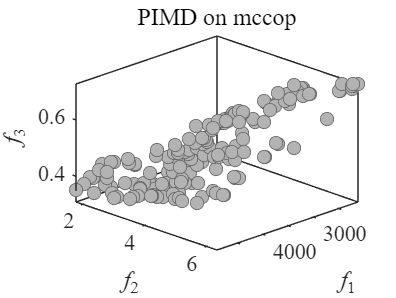


load("init_pop_100_4.mat");
platemo(4,init_pop,'algorithm',@PIMD,'problem',@mccop);


load("init_pop_100_5.mat");
platemo(5,init_pop,'algorithm',@PIMD,'problem',@mccop);

最终指标为, 充电时间: 3491 分钟, 温升: 2.84 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3643 分钟, 温升: 2.63 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 3311 分钟, 温升: 2.79 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 4279 分钟, 温升: 2.16 度, 消耗寿命: 0.37 %...
最终指标为, 充电时间: 3602 分钟, 温升: 2.75 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2829 分钟, 温升: 4.70 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3408 分钟, 温升: 3.00 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 2893 分钟, 温升: 4.97 度, 消耗寿命: 0.66 %...
最终指标为, 充电时间: 4555 分钟, 温升: 1.73 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3625 分钟, 温升: 3.23 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 2872 分钟, 温升: 5.14 度, 消耗寿命: 0.70 %...
最终指标为, 充电时间: 3308 分钟, 温升: 3.83 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3805 分钟, 温升: 3.65 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3393 分钟, 温升: 3.40 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3567 分钟, 温升: 2.86 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3150 分钟, 温升: 3.97 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 3345 分钟, 温升: 4.10 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 3320 分钟, 温升: 3.06 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 2890 分钟, 温升: 3.82 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3511 分钟, 温升: 2.63 度, 消耗寿命: 0.46 %...


最终指标为, 充电时间: 2882 分钟, 温升: 3.82 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3851 分钟, 温升: 2.86 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 11.00%), 51.25s passed...


最终指标为, 充电时间: 2870 分钟, 温升: 4.07 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 4088 分钟, 温升: 2.28 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 12.00%), 55.94s passed...


最终指标为, 充电时间: 2915 分钟, 温升: 4.06 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 3470 分钟, 温升: 2.83 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 13.00%), 60.53s passed...


最终指标为, 充电时间: 4131 分钟, 温升: 2.31 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3172 分钟, 温升: 3.44 度, 消耗寿命: 0.47 %...


PIMD on 3-objective 5-variable mccop ( 14.00%), 65.23s passed...


最终指标为, 充电时间: 3401 分钟, 温升: 3.36 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 3721 分钟, 温升: 3.07 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 15.00%), 69.98s passed...


最终指标为, 充电时间: 4101 分钟, 温升: 2.40 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 4067 分钟, 温升: 2.52 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 16.00%), 74.75s passed...


最终指标为, 充电时间: 4179 分钟, 温升: 2.60 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 2666 分钟, 温升: 4.67 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 17.00%), 79.69s passed...


最终指标为, 充电时间: 3855 分钟, 温升: 2.43 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3013 分钟, 温升: 3.26 度, 消耗寿命: 0.52 %...


PIMD on 3-objective 5-variable mccop ( 18.00%), 84.39s passed...


最终指标为, 充电时间: 4542 分钟, 温升: 2.18 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 3298 分钟, 温升: 2.82 度, 消耗寿命: 0.50 %...


PIMD on 3-objective 5-variable mccop ( 19.00%), 89.31s passed...


最终指标为, 充电时间: 4508 分钟, 温升: 2.24 度, 消耗寿命: 0.34 %...
最终指标为, 充电时间: 4769 分钟, 温升: 1.74 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 20.00%), 94.05s passed...


最终指标为, 充电时间: 2905 分钟, 温升: 3.70 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 3529 分钟, 温升: 3.41 度, 消耗寿命: 0.36 %...


PIMD on 3-objective 5-variable mccop ( 21.00%), 98.87s passed...


最终指标为, 充电时间: 2972 分钟, 温升: 3.84 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3360 分钟, 温升: 3.73 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 22.00%), 103.66s passed...


最终指标为, 充电时间: 2831 分钟, 温升: 4.01 度, 消耗寿命: 0.58 %...
最终指标为, 充电时间: 3619 分钟, 温升: 2.80 度, 消耗寿命: 0.40 %...


PIMD on 3-objective 5-variable mccop ( 23.00%), 107.88s passed...


最终指标为, 充电时间: 4473 分钟, 温升: 2.41 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 4742 分钟, 温升: 1.75 度, 消耗寿命: 0.37 %...


PIMD on 3-objective 5-variable mccop ( 24.00%), 112.32s passed...


最终指标为, 充电时间: 3684 分钟, 温升: 3.13 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 4800 分钟, 温升: 1.87 度, 消耗寿命: 0.35 %...


PIMD on 3-objective 5-variable mccop ( 25.00%), 116.82s passed...


最终指标为, 充电时间: 2666 分钟, 温升: 4.67 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 3390 分钟, 温升: 3.40 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 26.00%), 121.07s passed...


最终指标为, 充电时间: 3380 分钟, 温升: 3.36 度, 消耗寿命: 0.39 %...
最终指标为, 充电时间: 4374 分钟, 温升: 2.50 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 27.00%), 125.38s passed...


最终指标为, 充电时间: 4787 分钟, 温升: 1.88 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3826 分钟, 温升: 2.64 度, 消耗寿命: 0.38 %...


PIMD on 3-objective 5-variable mccop ( 28.00%), 129.50s passed...


最终指标为, 充电时间: 2885 分钟, 温升: 3.76 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 4643 分钟, 温升: 1.99 度, 消耗寿命: 0.34 %...


PIMD on 3-objective 5-variable mccop ( 29.00%), 133.56s passed...


最终指标为, 充电时间: 2609 分钟, 温升: 4.66 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3221 分钟, 温升: 3.25 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 30.00%), 137.47s passed...


最终指标为, 充电时间: 3837 分钟, 温升: 3.35 度, 消耗寿命: 0.32 %...
最终指标为, 充电时间: 2848 分钟, 温升: 3.86 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 31.00%), 141.73s passed...


最终指标为, 充电时间: 4784 分钟, 温升: 1.89 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3779 分钟, 温升: 3.43 度, 消耗寿命: 0.32 %...


PIMD on 3-objective 5-variable mccop ( 32.00%), 146.27s passed...


最终指标为, 充电时间: 4188 分钟, 温升: 2.61 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 4182 分钟, 温升: 2.10 度, 消耗寿命: 0.40 %...


PIMD on 3-objective 5-variable mccop ( 33.00%), 152.28s passed...


最终指标为, 充电时间: 4797 分钟, 温升: 1.87 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3977 分钟, 温升: 2.53 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 34.00%), 159.75s passed...


最终指标为, 充电时间: 4549 分钟, 温升: 2.04 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 4058 分钟, 温升: 2.82 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 35.00%), 166.53s passed...


最终指标为, 充电时间: 4556 分钟, 温升: 1.73 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3148 分钟, 温升: 3.64 度, 消耗寿命: 0.45 %...


PIMD on 3-objective 5-variable mccop ( 36.00%), 174.65s passed...


最终指标为, 充电时间: 3913 分钟, 温升: 2.58 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3110 分钟, 温升: 4.14 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 37.00%), 181.60s passed...


最终指标为, 充电时间: 3981 分钟, 温升: 2.96 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 37.50%), 185.27s passed...


最终指标为, 充电时间: 4410 分钟, 温升: 2.41 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 3266 分钟, 温升: 4.14 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 38.50%), 201.14s passed...


最终指标为, 充电时间: 3382 分钟, 温升: 2.94 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 4134 分钟, 温升: 2.26 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 39.50%), 207.32s passed...


最终指标为, 充电时间: 3365 分钟, 温升: 3.26 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3779 分钟, 温升: 3.43 度, 消耗寿命: 0.32 %...


PIMD on 3-objective 5-variable mccop ( 40.50%), 212.38s passed...


最终指标为, 充电时间: 4019 分钟, 温升: 2.53 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3197 分钟, 温升: 3.82 度, 消耗寿命: 0.40 %...


PIMD on 3-objective 5-variable mccop ( 41.50%), 218.01s passed...
最终指标为, 充电时间: 3828 分钟, 温升: 2.66 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3082 分钟, 温升: 4.15 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 42.50%), 223.59s passed...


最终指标为, 充电时间: 2945 分钟, 温升: 4.21 度, 消耗寿命: 0.59 %...
最终指标为, 充电时间: 2924 分钟, 温升: 4.23 度, 消耗寿命: 0.59 %...


PIMD on 3-objective 5-variable mccop ( 43.50%), 228.81s passed...


最终指标为, 充电时间: 2315 分钟, 温升: 5.29 度, 消耗寿命: 0.64 %...
最终指标为, 充电时间: 3365 分钟, 温升: 3.33 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 44.50%), 234.23s passed...


最终指标为, 充电时间: 4160 分钟, 温升: 2.65 度, 消耗寿命: 0.33 %...
最终指标为, 充电时间: 4237 分钟, 温升: 2.35 度, 消耗寿命: 0.44 %...


PIMD on 3-objective 5-variable mccop ( 45.50%), 239.87s passed...


最终指标为, 充电时间: 3317 分钟, 温升: 3.42 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3031 分钟, 温升: 4.14 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 46.50%), 245.40s passed...


最终指标为, 充电时间: 3332 分钟, 温升: 3.05 度, 消耗寿命: 0.44 %...
最终指标为, 充电时间: 4117 分钟, 温升: 2.37 度, 消耗寿命: 0.39 %...


PIMD on 3-objective 5-variable mccop ( 47.50%), 251.43s passed...


最终指标为, 充电时间: 3799 分钟, 温升: 2.98 度, 消耗寿命: 0.35 %...
最终指标为, 充电时间: 3165 分钟, 温升: 3.14 度, 消耗寿命: 0.53 %...


PIMD on 3-objective 5-variable mccop ( 48.50%), 258.37s passed...


最终指标为, 充电时间: 4601 分钟, 温升: 1.71 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 2806 分钟, 温升: 3.86 度, 消耗寿命: 0.57 %...


PIMD on 3-objective 5-variable mccop ( 49.50%), 264.22s passed...


最终指标为, 充电时间: 2891 分钟, 温升: 3.99 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3777 分钟, 温升: 3.65 度, 消耗寿命: 0.32 %...


PIMD on 3-objective 5-variable mccop ( 50.50%), 270.26s passed...


最终指标为, 充电时间: 3747 分钟, 温升: 3.56 度, 消耗寿命: 0.32 %...
最终指标为, 充电时间: 3199 分钟, 温升: 3.17 度, 消耗寿命: 0.46 %...


PIMD on 3-objective 5-variable mccop ( 51.50%), 276.19s passed...


最终指标为, 充电时间: 4601 分钟, 温升: 1.93 度, 消耗寿命: 0.36 %...
最终指标为, 充电时间: 3988 分钟, 温升: 2.96 度, 消耗寿命: 0.33 %...


PIMD on 3-objective 5-variable mccop ( 52.50%), 283.74s passed...


最终指标为, 充电时间: 3556 分钟, 温升: 3.05 度, 消耗寿命: 0.38 %...
最终指标为, 充电时间: 3301 分钟, 温升: 3.15 度, 消耗寿命: 0.43 %...


PIMD on 3-objective 5-variable mccop ( 53.50%), 288.65s passed...


最终指标为, 充电时间: 3338 分钟, 温升: 3.15 度, 消耗寿命: 0.42 %...
最终指标为, 充电时间: 4481 分钟, 温升: 1.78 度, 消耗寿命: 0.41 %...


PIMD on 3-objective 5-variable mccop ( 54.50%), 292.68s passed...


最终指标为, 充电时间: 2891 分钟, 温升: 3.68 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 2794 分钟, 温升: 4.00 度, 消耗寿命: 0.55 %...


PIMD on 3-objective 5-variable mccop ( 55.50%), 296.47s passed...


最终指标为, 充电时间: 3107 分钟, 温升: 4.14 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3659 分钟, 温升: 2.80 度, 消耗寿命: 0.42 %...


PIMD on 3-objective 5-variable mccop ( 56.50%), 300.51s passed...


最终指标为, 充电时间: 4196 分钟, 温升: 2.71 度, 消耗寿命: 0.32 %...
最终指标为, 充电时间: 3346 分钟, 温升: 3.31 度, 消耗寿命: 0.40 %...


PIMD on 3-objective 5-variable mccop ( 57.50%), 304.40s passed...


最终指标为, 充电时间: 3622 分钟, 温升: 2.80 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 3315 分钟, 温升: 3.22 度, 消耗寿命: 0.42 %...


%%%%%%%%%%%%%%%%%%%%%%%% soh = 90 ###############
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_90_1.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_90for70_200_1','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_90for70_200_1','EEI_DATA');
% 方法三
platemo(1,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(1,init_pop,'algorithm',@PIMD,'problem',@mccop);

% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_90_2.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_90for70_200_2','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_90for70_200_2','EEI_DATA');
% 方法三
platemo(2,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(2,init_pop,'algorithm',@PIMD,'problem',@mccop);

% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_90_3.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_90for70_200_3','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_90for70_200_3','EEI_DATA');
% 方法三
platemo(3,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(3,init_pop,'algorithm',@PIMD,'problem',@mccop);

% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_90_4.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_90for70_200_4','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_90for70_200_4','EEI_DATA');
% 方法三
platemo(4,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(4,init_pop,'algorithm',@PIMD,'problem',@mccop);

% 2025/07/05
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_90_5.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_90for70_200_5','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_90for70_200_5','EEI_DATA');
% 方法三
platemo(5,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(5,init_pop,'algorithm',@PIMD,'problem',@mccop);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%% soh = 80 ###############
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_80_1.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_80for70_200_1','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_80for70_200_1','EEI_DATA');
% 方法三
platemo(1,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(1,init_pop,'algorithm',@PIMD,'problem',@mccop);

% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_80_2.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_80for70_200_2','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_80for70_200_2','EEI_DATA');
% 方法三
platemo(2,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(2,init_pop,'algorithm',@PIMD,'problem',@mccop);

% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_80_3.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_80for70_200_3','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_80for70_200_3','EEI_DATA');
% 方法三
platemo(3,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(3,init_pop,'algorithm',@PIMD,'problem',@mccop);

% 2025/07/23
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_80_4.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_80for70_200_4','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_80for70_200_4','EEI_DATA');
% 方法三
platemo(4,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(4,init_pop,'algorithm',@PIMD,'problem',@mccop);

% 2025/07/05
% 规则是迁移到SOH=0.7
% 上下界设定
up = ones(1,5);
dn = zeros(1,5);
% 初始化种群（随机的）
init_pop = (up - dn).*rand(20,5) + dn;
save("init_pop_80_5.mat","init_pop");
% 两种方法的测试（方法一）
DB_ParEGO = ParEGO(init_pop);
ParEGO_DATA = DB_ParEGO;
save('result/ParEGO_DATA_80for70_200_5','ParEGO_DATA');
% 方法二
[DB_EEI,~] = TrOpt(init_pop);
EEI_DATA = DB_EEI;
save('result/EEI_DATA_80for70_200_5','EEI_DATA');
% 方法三
platemo(5,init_pop,'algorithm',@DISK,'problem',@mccop);
% 方法四
platemo(5,init_pop,'algorithm',@PIMD,'problem',@mccop);